# AuE-6600 | Dynamic Performance of Vehicles

## Capstone Project

**Authors:** Tanmay Samak, Chinmay Samak, Abhilash Tukkar

The goal of the graduate project is to apply techniques and methods learned in the Dynamics Performance of Vehicles class to an integrated problem with a significant simulation component.

**Vehicle Parameters:**

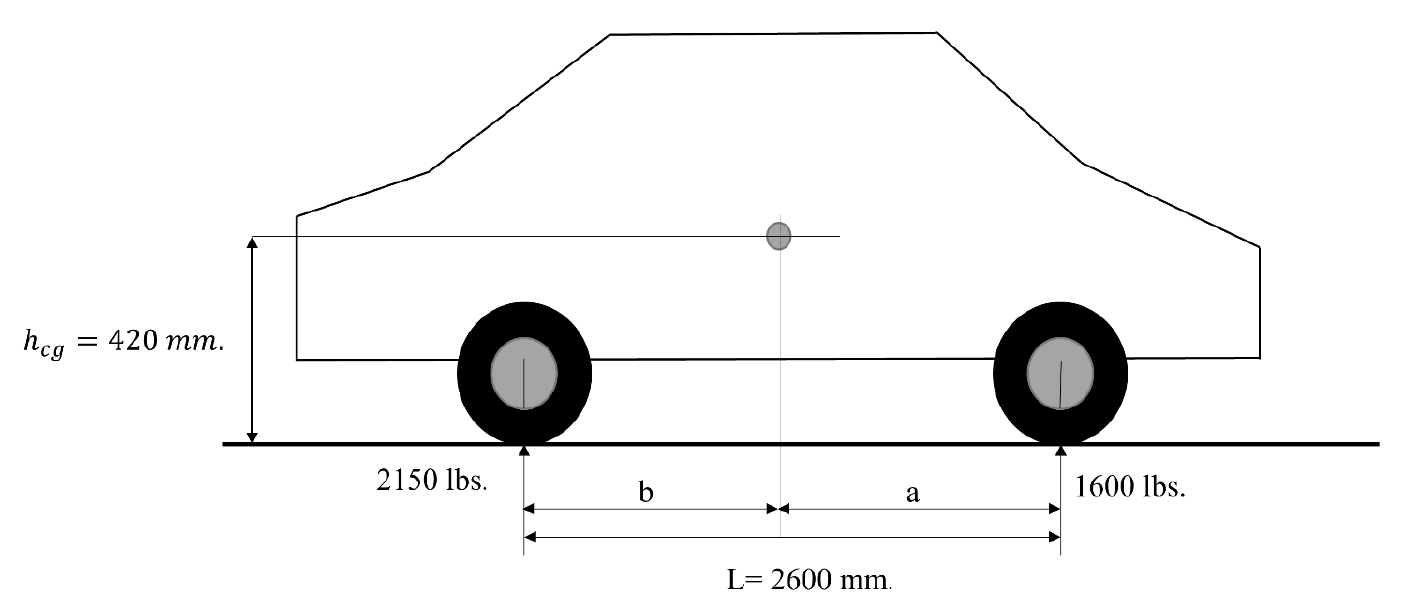

Note: lbs are not lbf

**Additional Parameters:**

- Yaw inertia: 2150 kg-m^2

- Front cornering stiffness: 1500 N/deg per tire (static load)

- Rear cornering stiffness: 1146 N/deg per tire (static load)

- Steering ratio: 15:1 (15 degree at the steering wheel = 1 degree at the front wheel)

- Trackwidth: 1.8 m

- Roll Stiffness distribution: 60% front

- Front roll center height: 0.33 ft

- Rear roll center height: 0.5 ft

- Total roll stiffness: 50000 Nm/rad

- Roll damping: 3500 Nm-s/rad

- Roll plane inertia: 700 kg-m^2

% Vehicle Parameters
m = (2150+1600)/2.205; % kg
Iz = 2150; % kg-m^2
l = 2.6; % m
w = 1.8; % m
m_a = (1-(1600/(2150+1600)))*l;
m_b = l-m_a;
C_alpha_F = 1500*(180/pi); % N/rad
C_alpha_R = 1146*(180/pi); % N/rad
SR = 15;
h_c = 0.42; % m
h_f = 0.33; % ft
h_f = h_f/3.281; % m
h_r = 0.5; % ft
h_r = h_r/3.281; % m
h_cr = h_c - (h_f + (h_r-h_f)/(l)*m_a);
k_SR = 50000; % Nm/rad
B_R = 3500; % Nm-s/rad
Ix = 700 + m*h_cr^2; % kg-m^2
r_a = 0.6;
r_b = 1-r_a;

**Maneuver Description:**

You are required to simulate the model for 2 different maneuvers that are described below. Based on the description, for each maneuver, you should create a vector of inputs for the simulation.

- The roadwheel steering angle is the input to your bicycle model. In the first maneuver, provide a step input for this steering angle. The vehicle is first being driven down a straight line at 74 mph for 7 seconds after which the driver holds the handwheel position constant at 45 degrees for 60 seconds. The handwheel position is then returned to 0 degrees and the maneuver is terminated

- The second maneuver is called the “fishhook maneuver” where you need to gradually increase the steering angle. To begin this maneuver, the vehicle is first driven in a straight line at 50mph. The driver must attempt to maintain this speed for 5 seconds. After that, the handwheel position is linearly increased from 0 to 270 degrees at a rate of 14.5 degrees per second. The handwheel position is held constant at 270 degrees for 4 seconds, after which the maneuver is concluded. The handwheel is then returned to 0 as a convenience to the driver.

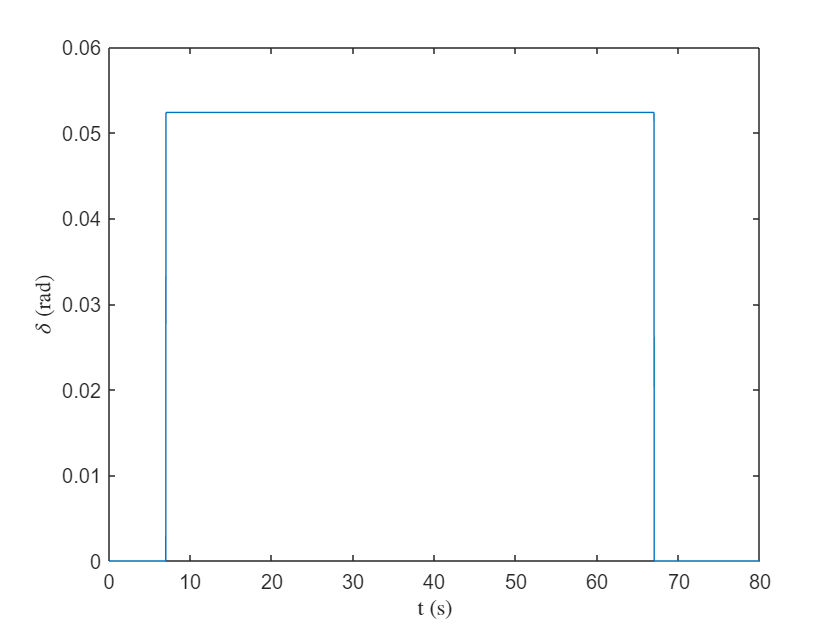

% Maneuver description
% Step maneuver
v_step = 74; % mph
v_step = v_step/2.237; % m/s
u_step = [ones(1,7000)*0 ones(1,60000)*(deg2rad(45)/SR) ones(1,13000)*0];
% Fishhook manuever
v_fishhook = 50; % mph
v_fishhook = v_fishhook/2.237; % m/s
u_fishhook = [ones(1,5000)*0 deg2rad(0:(14.5/1000):270)/SR ones(1,4000)*deg2rad(270)/SR ones(1,7379)*0];
% Plot steer input for step maneuver
t = linspace(0,length(u_step)/1000,length(u_step));
plot(t,u_step)
xlabel("t (s)","Interpreter","latex")
ylabel("$\delta$ (rad)","Interpreter","latex")

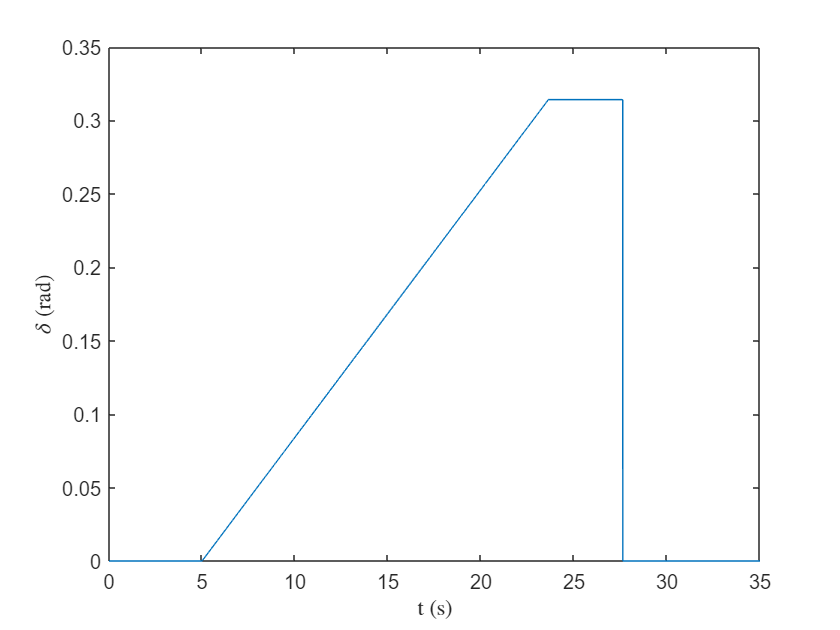

% Plot steer input for fishhook maneuver
t = linspace(0,length(u_fishhook)/1000,length(u_fishhook));
plot(t,u_fishhook)
xlabel("t (s)","Interpreter","latex")
ylabel("$\delta$ (rad)","Interpreter","latex")

### PART I - MODEL DEVELOPMENT

Here, we will derive a rear-steered vehicle model with planar dynamics (longitudinal, lateral, and yaw motion). The derivation of this model follows the same steps discussed in class for the Bicycle Model but includes driving/braking force. Using the provided vehicle parameters and the reference model in Fig. (2), answer the following questions.

A. Assuming an adapted ISO coordinate system, provide the free body diagram of the combined system with appropriate sign conventions.

B. Derive the equations of motion (EOM) for the rear steered vehicle utilizing generic force terms (i.e., Fy, Fx, Fyf, etc.). Then, utilize the corresponding expressions for the forces.

C. Rewrite the EOMs in state-space representation. You may apply small angle approximations. What are the eigenvalues of the system? Provide a plot of eigenvalues vs CG position.

D. Determine the steady-state characteristics (steering to instantaneous radius relationship as well as the vehicle slip angle relationship) of a rear steered vehicle through geometric analysis.

E. Derive the static stability derivatives for the rear steered vehicle. Comment on how different they are when compared to a front steered vehicle.

F. Derive the expressions for critical velocity and characteristic velocity of the rear steered vehicle.

G. Comment on your observations.

% Single-Track Model
a11 = ((C_alpha_F+C_alpha_R)/(m*v_step));
a12 = (((C_alpha_F*m_a)-(C_alpha_R*m_b))/(m*v_step^2))+1;
a21 = ((C_alpha_R*m_b)-(C_alpha_F*m_a))/(Iz);
a22 = -((C_alpha_F*m_a^2)+(C_alpha_R*m_b^2))/(Iz*v_step);
b1 = -(C_alpha_R)/(m*v_step);
b2 = -(C_alpha_R*m_b)/(Iz);
A = [a11 a12; a21 a22];
B = [b1; b2];
% Calculate Eigen Values
EV = eig(A);
fprintf("Eigen values of the system are:\n"); disp(EV);

Eigen values of the system are:
  -0.5633 + 3.9821i
  -0.5633 - 3.9821i



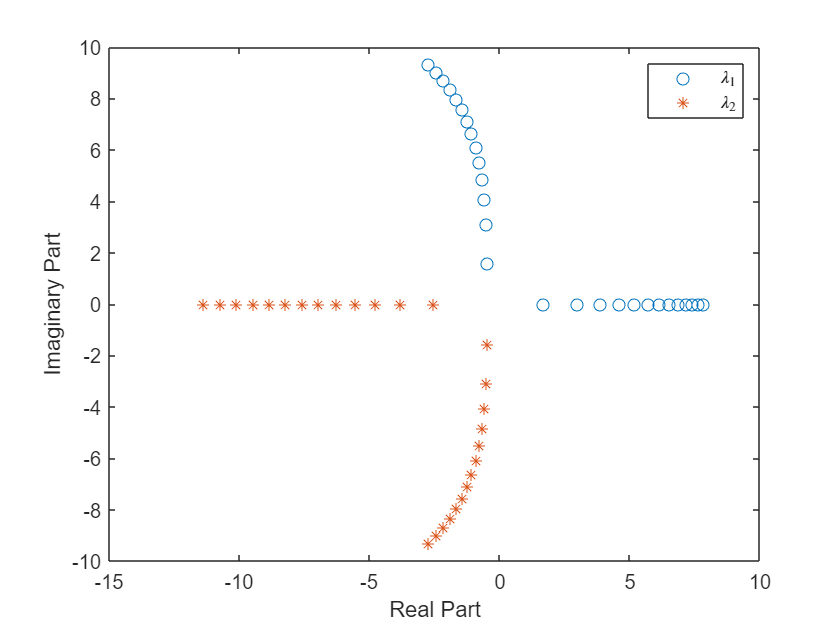

EV = [];
j = 1;
for i = 0:0.1:l
    % Single-Track Model
    a = i;
    b = l-a;
    a11 = ((C_alpha_F+C_alpha_R)/(m*v_step));
    a12 = (((C_alpha_F*a)-(C_alpha_R*b))/(m*v_step^2))+1;
    a21 = ((C_alpha_R*b)-(C_alpha_F*a))/(Iz);
    a22 = -((C_alpha_F*a^2)+(C_alpha_R*b^2))/(Iz*v_step);
    b1 = -(C_alpha_R)/(m*v_step);
    b2 = -(C_alpha_R*b)/(Iz);
    A = [a11 a12; a21 a22];
    B = [b1; b2];
    % Calculate Eigen Values
    EV(:,j) = eig(A);
    j = j+1;
end
% Plot Eigen Values
figure()
plot(EV(1,:),'o')
hold on
plot(EV(2,:),'*')
xlabel("Real Part")
ylabel("Imaginary Part")
legend("$\lambda_1$","$\lambda_2$","Interpreter","latex")

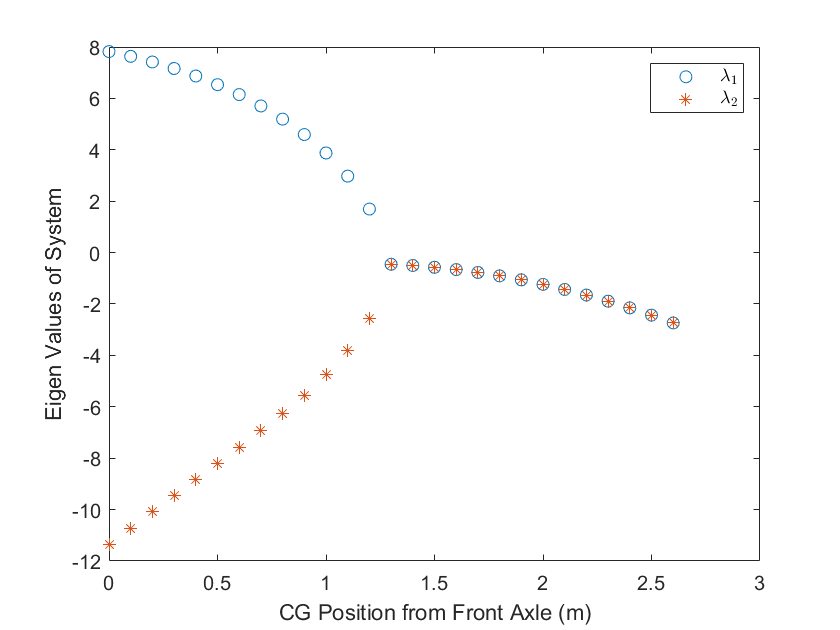

% Plot Eigen Values vs CG Position
CG_pos = 0:0.1:l;
figure()
plot(CG_pos,real(EV(1,:)),'o')
hold on
plot(CG_pos,real(EV(2,:)),'*')
xlabel("CG Position from Front Axle (m)")
ylabel("Eigen Values of System")
legend("$\lambda_1$","$\lambda_2$","Interpreter","latex")

### PART II - MODEL SIMULATION

Now that the system has been developed, let us test the system under different conditions.

A. Using the input generated and conditions in the assignment 6, test your model for both maneuvers.

            a. Provide plots for each state for both cases.

            b. Provide plots of the trajectories of center of gravity of the vehicle in inertial coordinates. Also plot the velocity vector in inertial coordinates.

B. Now expand your model from Part I to include the non-linear tire model as well as load transfer with roll dynamics.

C. For each of the following vehicle conditions, Determine the understeer gradient

            a. (Front weight distribution, Front roll stiffness distribution) = (60%, 60%)

            b. (Front weight distribution, Front roll stiffness distribution) = (55%, 46%)

            c. (Front weight distribution, Front roll stiffness distribution) = (50%, 60%)

D. Comment on your observations

### Solution II

**Part A**

1. Step Maneuver

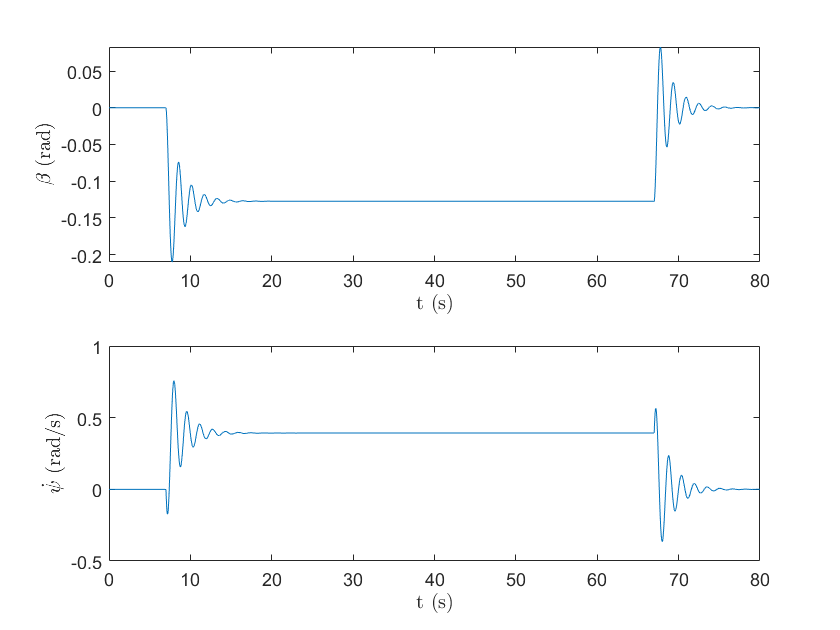

% Single-Track Model
a11 = ((C_alpha_F+C_alpha_R)/(m*v_step));
a12 = (((C_alpha_F*m_a)-(C_alpha_R*m_b))/(m*v_step^2))+1;
a21 = ((C_alpha_R*m_b)-(C_alpha_F*m_a))/(Iz);
a22 = -((C_alpha_F*m_a^2)+(C_alpha_R*m_b^2))/(Iz*v_step);
b1 = -(C_alpha_R)/(m*v_step);
b2 = -(C_alpha_R*m_b)/(Iz);
A = [a11 a12; a21 a22];
B = [b1; b2];
% Initialization
dt = 0.001; % s
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;
% Simulation at each millisecond
for t=1:80000
    X_dot(:,t) = A*X(:,t)+B*u_step(t);
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v_step*cos(Psi(t)-Beta(t));
    Vy(t) = v_step*sin(Psi(t)-Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
% Plot states
t=1:80000;
figure()
subplot(2,1,1)
plot(t/1000,X(1,1:end-1))
xlabel("t (s)","Interpreter","latex")
ylabel("$\beta$ (rad)","Interpreter","latex")
subplot(2,1,2)
plot(t/1000,X(2,1:end-1))
xlabel("t (s)","Interpreter","latex")
ylabel("$\dot{\psi}$ (rad/s)","Interpreter","latex")

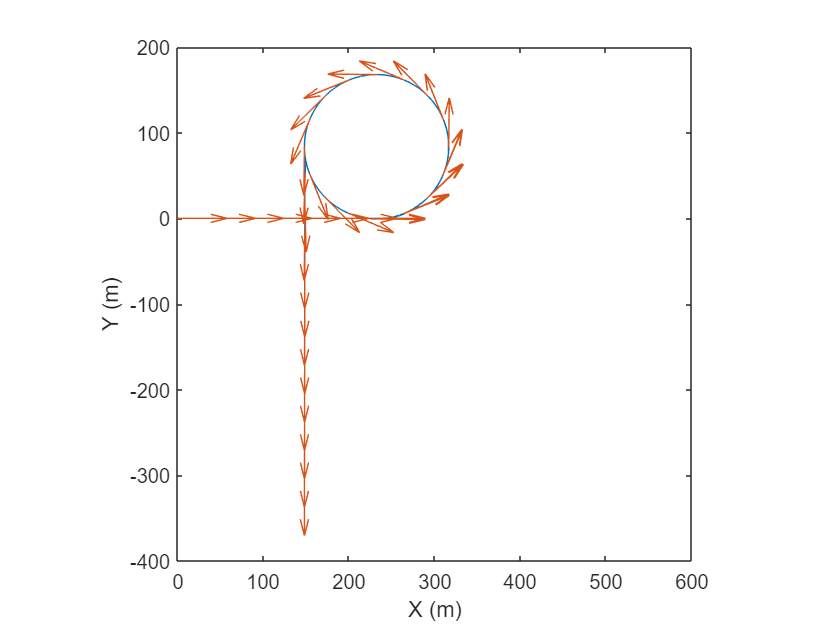

% Plot trajectory
figure()
plot(Px(1:end-1),Py(1:end-1))
hold on;
quiver(Px(1:1000:end-1000),Py(1:1000:end-1000),Vx(1:1000:end),Vy(1:1000:end))
hold off;
xlabel("X (m)")
ylabel("Y (m)")
xlim([0,600])
ylim([-400,200])
pbaspect([1 1 1])

2. Fishhook Maneuver

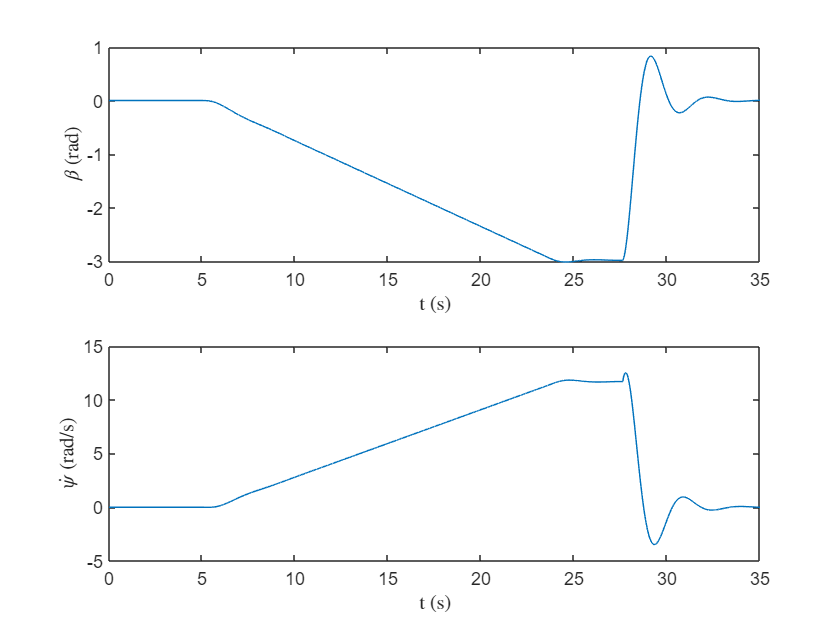

% Single-Track Model
a11 = ((C_alpha_F+C_alpha_R)/(m*v_fishhook));
a12 = (((C_alpha_F*m_a)-(C_alpha_R*m_b))/(m*v_fishhook^2))+1;
a21 = ((C_alpha_R*m_b)-(C_alpha_F*m_a))/(Iz);
a22 = -((C_alpha_F*m_a^2)+(C_alpha_R*m_b^2))/(Iz*v_fishhook);
b1 = -(C_alpha_R)/(m*v_fishhook);
b2 = -(C_alpha_R*m_b)/(Iz);
A = [a11 a12; a21 a22];
B = [b1; b2];
% Initialization
dt = 0.001; % s
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;
% Simulation at each millisecond
for t=1:35000
    X_dot(:,t) = A*X(:,t)+B*u_fishhook(t);
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v_fishhook*cos(Psi(t)-Beta(t));
    Vy(t) = v_fishhook*sin(Psi(t)-Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
% Plot states
t=1:35000;
figure()
subplot(2,1,1)
plot(t/1000,X(1,1:end-1))
xlabel("t (s)","Interpreter","latex")
ylabel("$\beta$ (rad)","Interpreter","latex")
subplot(2,1,2)
plot(t/1000,X(2,1:end-1))
xlabel("t (s)","Interpreter","latex")
ylabel("$\dot{\psi}$ (rad/s)","Interpreter","latex")

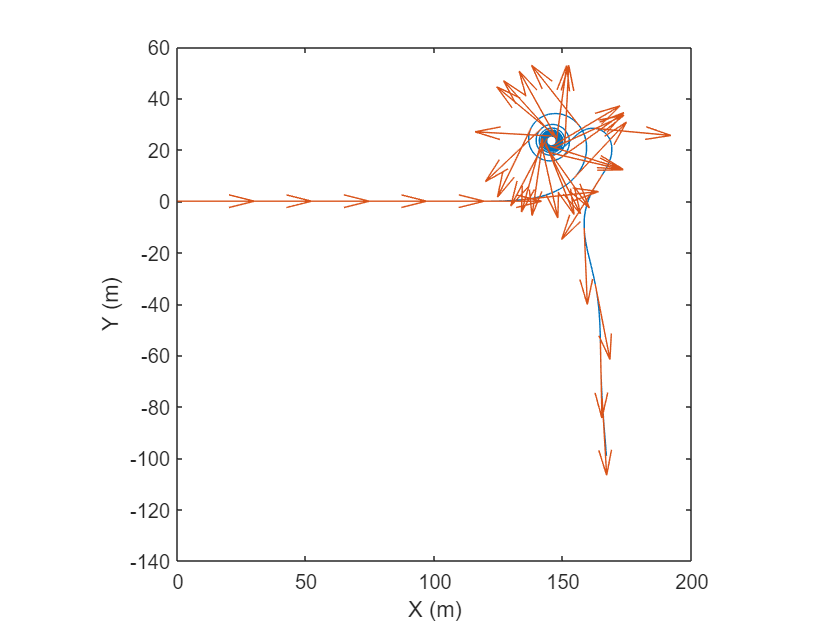

% Plot trajectory
figure()
plot(Px(1:end-1),Py(1:end-1))
hold on;
quiver(Px(1:1000:end-1000),Py(1:1000:end-1000),Vx(1:1000:end),Vy(1:1000:end))
hold off;
xlabel("X (m)")
ylabel("Y (m)")
xlim([0,200])
ylim([-140,60])
pbaspect([1 1 1])

**Part B**

1. Step Maneuver with Non-Linear Tire Model Considering Load Transfer and Roll Dynamics

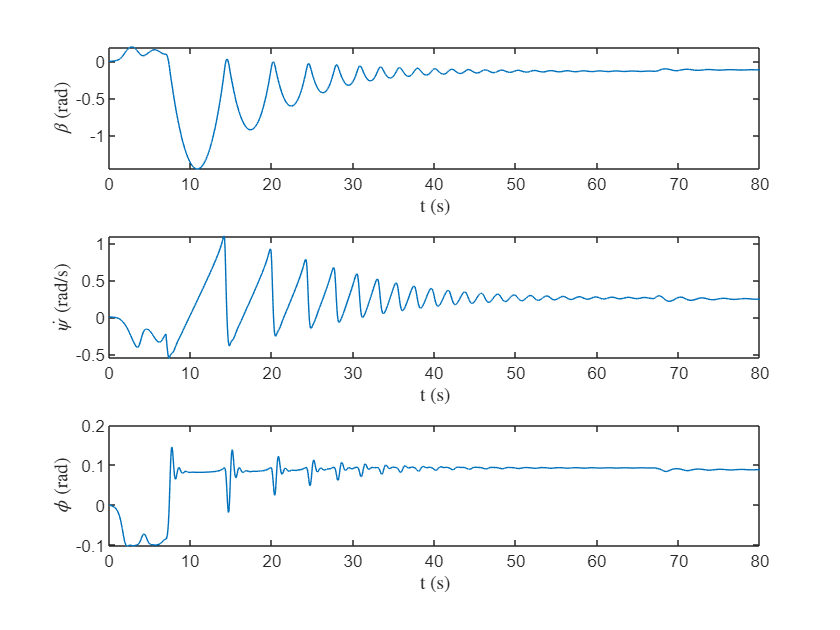

% Initialization
dt = 0.001; % s
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
B_dot = 0;
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;
Phi = [];
Phi(1) = 0;
Phi_dot = [];
Phi_dot(1) = 0;
Phi_ddot = [];
% Static load
S_fl = 0.5*(m_b/l)*m*9.81;
S_fr = 0.5*(m_b/l)*m*9.81;
S_rl = 0.5*(m_a/l)*m*9.81;
S_rr = 0.5*(m_a/l)*m*9.81;
% Simulation at each millisecond
for t=1:80000
    a_y = v_step*(X(2,t)-B_dot);
    Phi_ddot(t) = (1/Ix)*(m*a_y*h_cr + m*9.81*h_cr*Phi(t) - B_R*Phi_dot(t) - k_SR*Phi(t));
    Phi_dot(t+1) = Phi_dot(t) + Phi_ddot(t)*dt;
    Phi(t+1) = Phi(t) + Phi_dot(t)*dt;
    dW_f = (r_a*k_SR*Phi(t))/w + m*a_y*(m_b/l)*(h_f/w);
    dW_r = (r_b*k_SR*Phi(t))/w + m*a_y*(m_a/l)*(h_r/w);
    Fz_fl = S_fl - dW_f;
    Fz_fr = S_fr + dW_f;
    Fz_rl = S_rl - dW_r;
    Fz_rr = S_rr + dW_r;
    alpha_f = -(X(2,t)*m_a)/v_step - X(1,t);
    alpha_r = u_step(t) + (X(2,t)*m_b)/v_step - X(1,t);
    Fy_fl = -nonlintire(alpha_f, Fz_fl, v_step);
    Fy_fr = -nonlintire(alpha_f, Fz_fr, v_step);
    Fy_rl = -nonlintire(alpha_r, Fz_rl, v_step);
    Fy_rr = -nonlintire(alpha_r, Fz_rr, v_step);
    Fy_f = Fy_fl+Fy_fr;
    Fy_r = Fy_rl+Fy_rr;
    X_dot(:,t) = [X(2,t) - (Fy_f+Fy_r)/(m*v_step);
                  (Fy_f*m_a-Fy_r*m_b)/(Iz)];
    B_dot = X_dot(1,t);
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v_step*cos(Psi(t)-Beta(t));
    Vy(t) = v_step*sin(Psi(t)-Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
% Plot states
t=1:80000;
figure()
subplot(3,1,1)
plot(t/1000,X(1,1:end-1))
xlabel("t (s)","Interpreter","latex")
ylabel("$\beta$ (rad)","Interpreter","latex")
subplot(3,1,2)
plot(t/1000,X(2,1:end-1))
xlabel("t (s)","Interpreter","latex")
ylabel("$\dot{\psi}$ (rad/s)","Interpreter","latex")
subplot(3,1,3)
plot(t/1000,Phi(1:end-1))
xlabel("t (s)","Interpreter","latex")
ylabel("$\phi$ (rad)","Interpreter","latex")

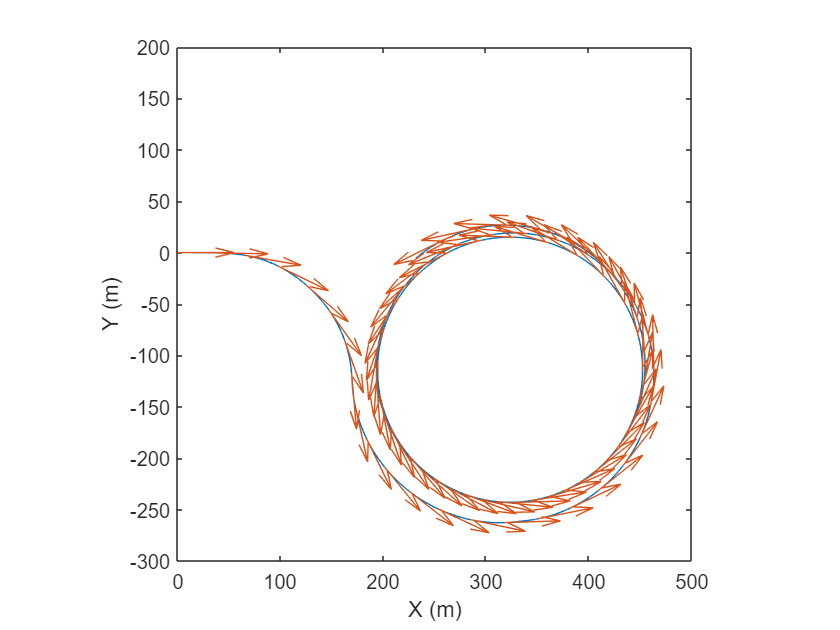

% Plot trajectory
figure()
plot(Px(1:end-1),Py(1:end-1))
hold on;
quiver(Px(1:1000:end-1000),Py(1:1000:end-1000),Vx(1:1000:end),Vy(1:1000:end))
hold off;
xlabel("X (m)")
ylabel("Y (m)")
xlim([0,500])
ylim([-300,200])
pbaspect([1 1 1])

2. Fishhook Maneuver with Non-Linear Tire Model Considering Load Transfer and Roll Dynamics

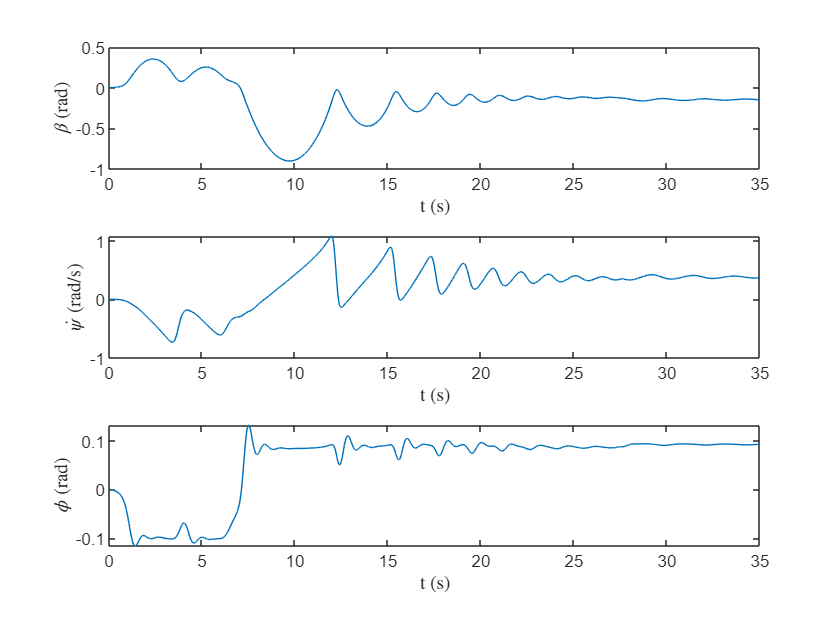

% Initialization
dt = 0.001; % s
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
B_dot = 0;
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;
Phi = [];
Phi(1) = 0;
Phi_dot = [];
Phi_dot(1) = 0;
Phi_ddot = [];
% Static load
S_fl = 0.5*(m_b/l)*m*9.81;
S_fr = 0.5*(m_b/l)*m*9.81;
S_rl = 0.5*(m_a/l)*m*9.81;
S_rr = 0.5*(m_a/l)*m*9.81;
% Simulation at each millisecond
for t=1:35000
    a_y = v_fishhook*(X(2,t)-B_dot);
    Phi_ddot(t) = (1/Ix)*(m*a_y*h_cr + m*9.81*h_cr*Phi(t) - B_R*Phi_dot(t) - k_SR*Phi(t));
    Phi_dot(t+1) = Phi_dot(t) + Phi_ddot(t)*dt;
    Phi(t+1) = Phi(t) + Phi_dot(t)*dt;
    dW_f = (r_a*k_SR*Phi(t))/w + m*a_y*(m_b/l)*(h_f/w);
    dW_r = (r_b*k_SR*Phi(t))/w + m*a_y*(m_a/l)*(h_r/w);
    Fz_fl = S_fl - dW_f;
    Fz_fr = S_fr + dW_f;
    Fz_rl = S_rl - dW_r;
    Fz_rr = S_rr + dW_r;
    alpha_f = -(X(2,t)*m_a)/v_fishhook - X(1,t);
    alpha_r = u_fishhook(t) + (X(2,t)*m_b)/v_fishhook - X(1,t);
    Fy_fl = -nonlintire(alpha_f, Fz_fl, v_fishhook);
    Fy_fr = -nonlintire(alpha_f, Fz_fr, v_fishhook);
    Fy_rl = -nonlintire(alpha_r, Fz_rl, v_fishhook);
    Fy_rr = -nonlintire(alpha_r, Fz_rr, v_fishhook);
    Fy_f = Fy_fl+Fy_fr;
    Fy_r = Fy_rl+Fy_rr;
    X_dot(:,t) = [X(2,t) - (Fy_f+Fy_r)/(m*v_fishhook);
                  (Fy_f*m_a-Fy_r*m_b)/(Iz)];
    B_dot = X_dot(1,t);
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v_fishhook*cos(Psi(t)-Beta(t));
    Vy(t) = v_fishhook*sin(Psi(t)-Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
% Plot states
t=1:35000;
figure()
subplot(3,1,1)
plot(t/1000,X(1,1:end-1))
xlabel("t (s)","Interpreter","latex")
ylabel("$\beta$ (rad)","Interpreter","latex")
subplot(3,1,2)
plot(t/1000,X(2,1:end-1))
xlabel("t (s)","Interpreter","latex")
ylabel("$\dot{\psi}$ (rad/s)","Interpreter","latex")
subplot(3,1,3)
plot(t/1000,Phi(1:end-1))
xlabel("t (s)","Interpreter","latex")
ylabel("$\phi$ (rad)","Interpreter","latex")

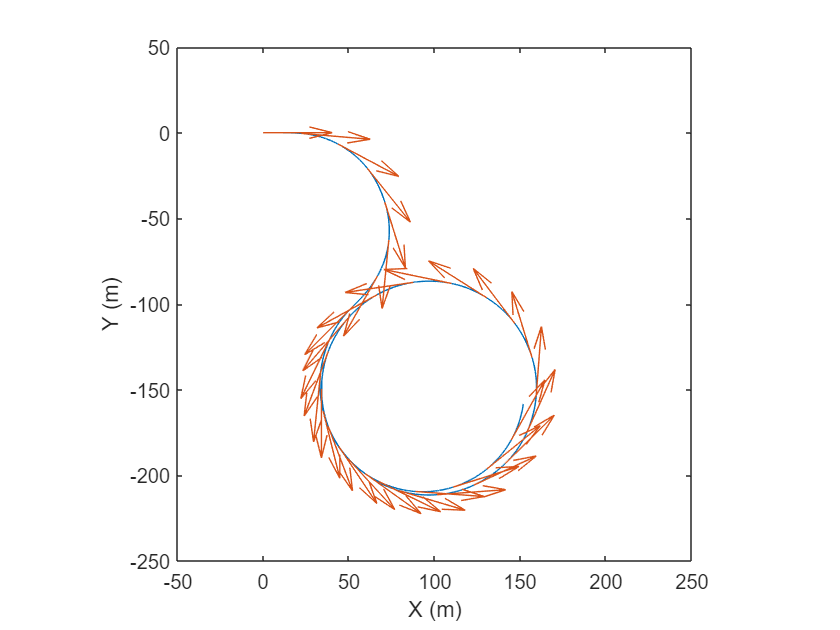

% Plot trajectory
figure()
plot(Px(1:end-1),Py(1:end-1))
hold on;
quiver(Px(1:1000:end-1000),Py(1:1000:end-1000),Vx(1:1000:end),Vy(1:1000:end))
hold off;
xlabel("X (m)")
ylabel("Y (m)")
xlim([-50,250])
ylim([-250,50])
pbaspect([1 1 1])

**Part C**

1. Step Maneuver with Non-Linear Tire Model Considering Load Transfer and Roll Dynamics

Front mass distribution: 60%, Front roll stiffness distribution: 60%

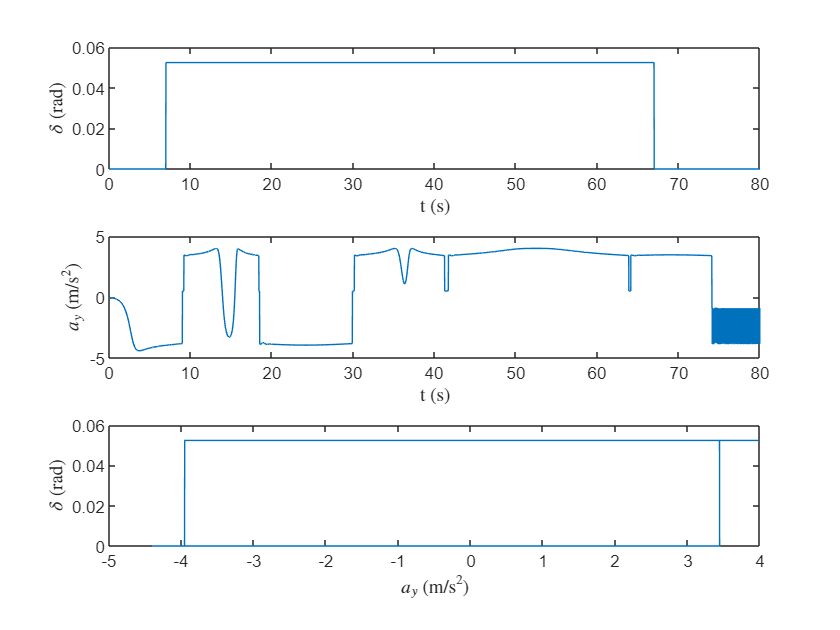

UG for step maneuver with non-linear tire model, with load transfer is 0.0116 rad-s^2/m

Front mass distribution: 55%, Front roll stiffness distribution: 46%

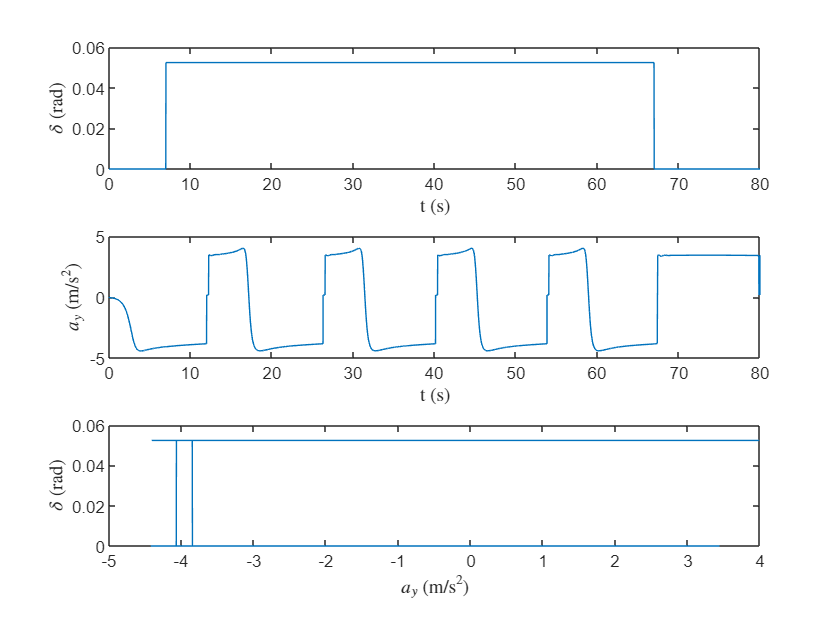

UG for step maneuver with non-linear tire model, with load transfer is 0.0129 rad-s^2/m

Front mass distribution: 50%, Front roll stiffness distribution: 60%

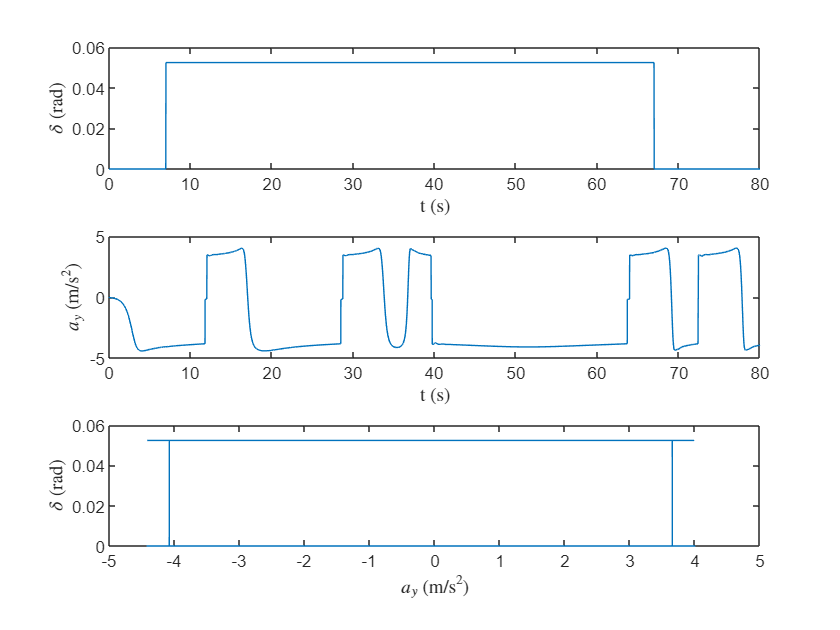

UG for step maneuver with non-linear tire model, with load transfer is 0.0121 rad-s^2/m

m_a_arr = [1-0.6, 1-0.55, 1-0.5];
r_a_arr = [0.6, 0.46, 0.6];
for i = 1:length(m_a_arr)
    % Choose m_a and r_a
    m_a_i = m_a_arr(i);
    m_b_i = 1-m_a_i;
    r_a_i = r_a_arr(i);
    r_b_i = 1-r_a_i;
    fprintf("Front mass distribution: %.0f%%, Front roll stiffness distribution: %.0f%%",100-m_a_i*100,r_a_i*100)
    % Initialization
    dt = 0.001; % s
    X = [];
    X(:,1) = [0;0];
    X_dot = [];
    Psi = [];
    Psi(1) = 0;
    Beta = [];
    B_dot = 0;
    Vx = [];
    Vy = [];
    Px = [];
    Px(1) = 0;
    Py = [];
    Py(1) = 0;
    Phi = [];
    Phi(1) = 0;
    Phi_dot = [];
    Phi_dot(1) = 0;
    Phi_ddot = [];
    a_y = [];
    alpha_f = [];
    alpha_r = [];
    % Static load
    S_fl = 0.5*(m_b_i/l)*m*9.81;
    S_fr = 0.5*(m_b_i/l)*m*9.81;
    S_rl = 0.5*(m_a_i/l)*m*9.81;
    S_rr = 0.5*(m_a_i/l)*m*9.81;
    % Simulation at each millisecond
    for t=1:80000
        a_y(t) = v_step*(X(2,t)-B_dot);
        Phi_ddot(t) = (1/Ix)*(m*a_y(t)*h_cr + m*9.81*h_cr*Phi(t) - B_R*Phi_dot(t) - k_SR*Phi(t));
        Phi_dot(t+1) = Phi_dot(t) + Phi_ddot(t)*dt;
        Phi(t+1) = Phi(t) + Phi_dot(t)*dt;
        dW_f = (r_a_i*k_SR*Phi(t))/w + m*a_y(t)*(m_b_i/l)*(h_f/w);
        dW_r = (r_b_i*k_SR*Phi(t))/w + m*a_y(t)*(m_a_i/l)*(h_r/w);
        Fz_fl = S_fl - dW_f;
        Fz_fr = S_fr + dW_f;
        Fz_rl = S_rl - dW_r;
        Fz_rr = S_rr + dW_r;
        alpha_f(t) = -(X(2,t)*m_a_i)/v_step - X(1,t);
        alpha_r(t) = u_step(t) + (X(2,t)*m_b_i)/v_step - X(1,t);
        Fy_fl = -nonlintire(alpha_f(t), Fz_fl, v_step);
        Fy_fr = -nonlintire(alpha_f(t), Fz_fr, v_step);
        Fy_rl = -nonlintire(alpha_r(t), Fz_rl, v_step);
        Fy_rr = -nonlintire(alpha_r(t), Fz_rr, v_step);
        Fy_f = Fy_fl+Fy_fr;
        Fy_r = Fy_rl+Fy_rr;
        X_dot(:,t) = [X(2,t) - (Fy_f+Fy_r)/(m*v_step);
                      (Fy_f*m_a_i-Fy_r*m_b_i)/(Iz)];
        B_dot = X_dot(1,t);
        X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
        Beta(t) = X(1,t);
        Psi(t+1) = Psi(t) + X(2,t)*dt;
        Vx(t) = v_step*cos(Psi(t)-Beta(t));
        Vy(t) = v_step*sin(Psi(t)-Beta(t));
        Px(t+1) = Px(t) + Vx(t)*dt;
        Py(t+1) = Py(t) + Vy(t)*dt;
    end
    % Understeer gradient
    t = 1:80000;
    figure()
    subplot(3,1,1)
    plot(t/1000,u_step)
    xlabel("t (s)","Interpreter","latex")
    ylabel("$\delta$ (rad)","Interpreter","latex")
    subplot(3,1,2)
    plot(t/1000,a_y)
    xlabel("t (s)","Interpreter","latex")
    ylabel("$a_y$ (m/s$^2$)","Interpreter","latex")
    subplot(3,1,3)
    plot(a_y,u_step)
    hold off;
    xlabel("$a_y$ (m/s$^2$)","Interpreter","latex")
    ylabel("$\delta$ (rad)","Interpreter","latex")
    UG = (alpha_f(21000)-alpha_r(21000))/a_y(21000);
    fprintf("UG for step maneuver with non-linear tire model, with load transfer is %.4f rad-s^2/m", UG);
end

2. Fishhook Maneuver with Non-Linear Tire Model Considering Load Transfer and Roll Dynamics

Front mass distribution: 60%, Front roll stiffness distribution: 60%

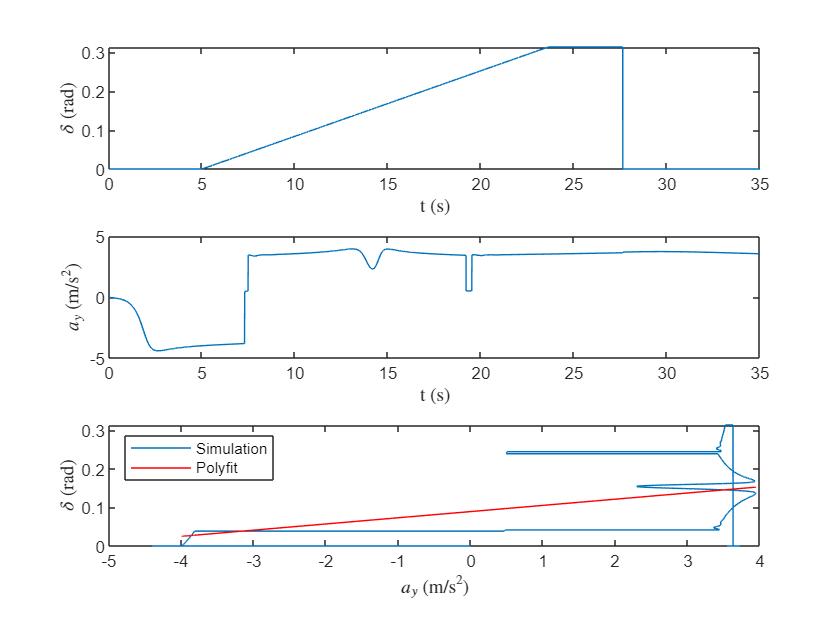

UG for fishhook maneuver with non-linear tire model, with load transfer is 0.0109 rad-s^2/m


Front mass distribution: 55%, Front roll stiffness distribution: 46%

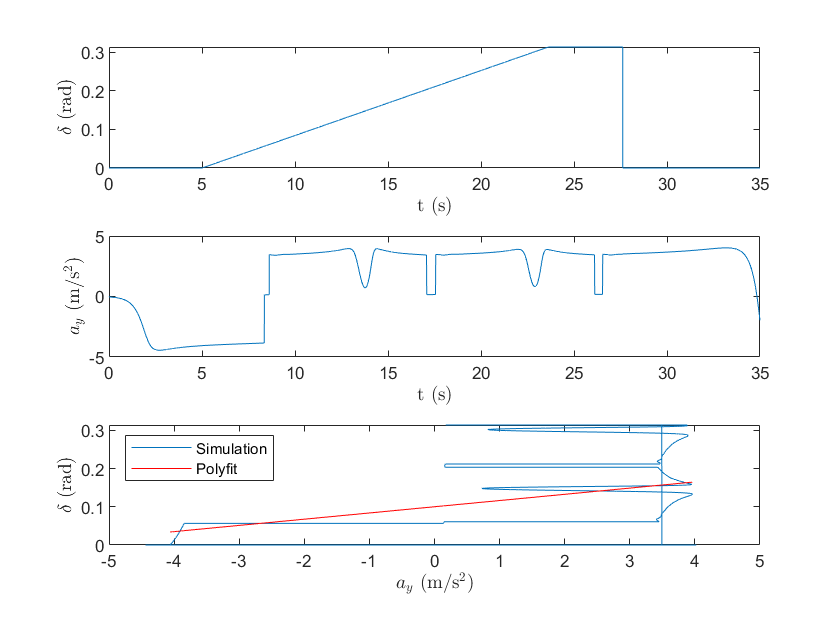

UG for fishhook maneuver with non-linear tire model, with load transfer is 0.0111 rad-s^2/m


Front mass distribution: 50%, Front roll stiffness distribution: 60%

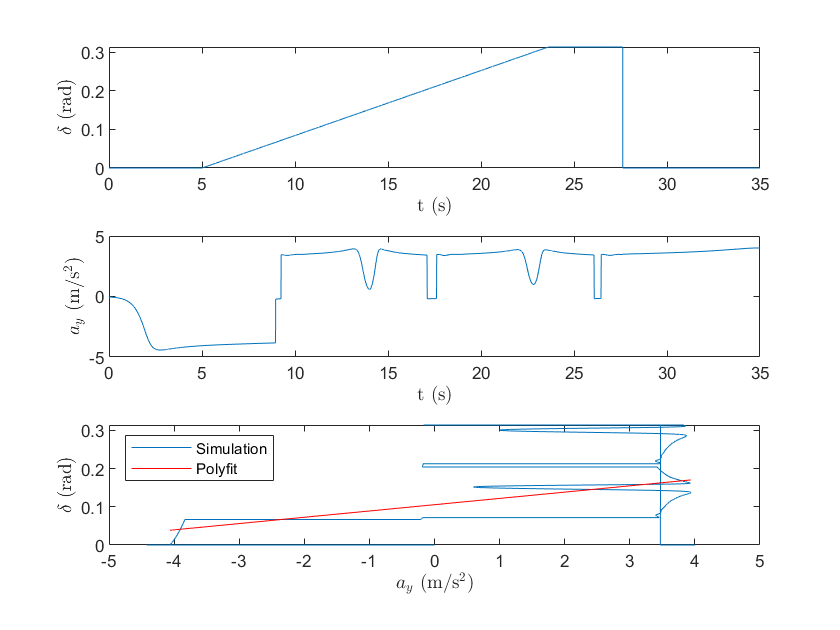

UG for fishhook maneuver with non-linear tire model, with load transfer is 0.0113 rad-s^2/m


m_a_arr = [1-0.6, 1-0.55, 1-0.5];
r_a_arr = [0.6, 0.46, 0.6];
for i = 1:length(m_a_arr)
    % Choose m_a and r_a
    m_a_i = m_a_arr(i);
    m_b_i = 1-m_a_i;
    r_a_i = r_a_arr(i);
    r_b_i = 1-r_a;
    fprintf("Front mass distribution: %.0f%%, Front roll stiffness distribution: %.0f%%",100-m_a_i*100,r_a_i*100)
    % Initialization
    dt = 0.001; % s
    X = [];
    X(:,1) = [0;0];
    X_dot = [];
    Psi = [];
    Psi(1) = 0;
    Beta = [];
    B_dot = 0;
    Vx = [];
    Vy = [];
    Px = [];
    Px(1) = 0;
    Py = [];
    Py(1) = 0;
    Phi = [];
    Phi(1) = 0;
    Phi_dot = [];
    Phi_dot(1) = 0;
    Phi_ddot = [];
    a_y = [];
    % Static load
    S_fl = 0.5*(m_b_i/l)*m*9.81;
    S_fr = 0.5*(m_b_i/l)*m*9.81;
    S_rl = 0.5*(m_a_i/l)*m*9.81;
    S_rr = 0.5*(m_a_i/l)*m*9.81;
    % Simulation at each millisecond
    for t=1:35000
        a_y(t) = v_fishhook*(X(2,t)-B_dot);
        Phi_ddot(t) = (1/Ix)*(m*a_y(t)*h_cr + m*9.81*h_cr*Phi(t) - B_R*Phi_dot(t) - k_SR*Phi(t));
        Phi_dot(t+1) = Phi_dot(t) + Phi_ddot(t)*dt;
        Phi(t+1) = Phi(t) + Phi_dot(t)*dt;
        dW_f = (r_a_i*k_SR*Phi(t))/w + m*a_y(t)*(m_b_i/l)*(h_f/w);
        dW_r = (r_b_i*k_SR*Phi(t))/w + m*a_y(t)*(m_a_i/l)*(h_r/w);
        Fz_fl = S_fl - dW_f;
        Fz_fr = S_fr + dW_f;
        Fz_rl = S_rl - dW_r;
        Fz_rr = S_rr + dW_r;
        alpha_f = -(X(2,t)*m_a_i)/v_fishhook - X(1,t);
        alpha_r = u_fishhook(t) + (X(2,t)*m_b_i)/v_fishhook - X(1,t);
        Fy_fl = -nonlintire(alpha_f, Fz_fl, v_fishhook);
        Fy_fr = -nonlintire(alpha_f, Fz_fr, v_fishhook);
        Fy_rl = -nonlintire(alpha_r, Fz_rl, v_fishhook);
        Fy_rr = -nonlintire(alpha_r, Fz_rr, v_fishhook);
        Fy_f = Fy_fl+Fy_fr;
        Fy_r = Fy_rl+Fy_rr;
        X_dot(:,t) = [X(2,t) - (Fy_f+Fy_r)/(m*v_fishhook);
                      (Fy_f*m_a_i-Fy_r*m_b_i)/(Iz)];
        B_dot = X_dot(1,t);
        X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
        Beta(t) = X(1,t);
        Psi(t+1) = Psi(t) + X(2,t)*dt;
        Vx(t) = v_fishhook*cos(Psi(t)-Beta(t));
        Vy(t) = v_fishhook*sin(Psi(t)-Beta(t));
        Px(t+1) = Px(t) + Vx(t)*dt;
        Py(t+1) = Py(t) + Vy(t)*dt;
    end
    % Understeer gradient
    t = 1:35000;
    figure()
    subplot(3,1,1)
    plot(t/1000,u_fishhook)
    xlabel("t (s)","Interpreter","latex")
    ylabel("$\delta$ (rad)","Interpreter","latex")
    subplot(3,1,2)
    plot(t/1000,a_y)
    xlabel("t (s)","Interpreter","latex")
    ylabel("$a_y$ (m/s$^2$)","Interpreter","latex")
    subplot(3,1,3)
    plot(a_y,u_fishhook)
    hold on;
    UG_poly = polyfit(a_y(5000:20000), u_fishhook(5000:20000), 1);
    plot(a_y(5000:20000),polyval(UG_poly,a_y(5000:20000)),'r');
    hold off;
    xlabel("$a_y$ (m/s$^2$)","Interpreter","latex")
    ylabel("$\delta$ (rad)","Interpreter","latex")
    legend("Simulation","Polyfit",'Location','NW')
    UG = polyder(UG_poly) - l/(v_fishhook^2);
    fprintf("UG for fishhook maneuver with non-linear tire model, with load transfer is %.4f rad-s^2/m\n", UG);
end

### PART III - TWO-AXLE STEERING

Now that you had developed a vehicle model with rear steering input, it is time to combine front and rear axle steering to arrive at a 2-axle steering system. Develop a state-space representation of a 2-axle steering system. $\delta_f$ represents front steering angle and $\delta_r$ represents rear steering angle.

**Input conditions:**

- $\delta_f$** input:** Step input and fishhook maneuver from assignment 6

- $\delta_r$** input:** Develop a strategy for rear steer angle such that vehicle is always at Neutral steer

A. Provide plots for states of the system and trajectories of center of gravity of the vehicle in inertial coordinates. Also plot the velocity vector in inertial coordinates.

B. Now repeat part A with non-linear tire model and roll dynamics. Provide plots for states of the system and trajectories of center of gravity of the vehicle in inertial coordinates. Also plot the velocity vector in inertial coordinates.

C. Compare the performance of the strategy for part A and part B. Provide the explanation

### Solution III

**Part A**

1. Step Maneuver

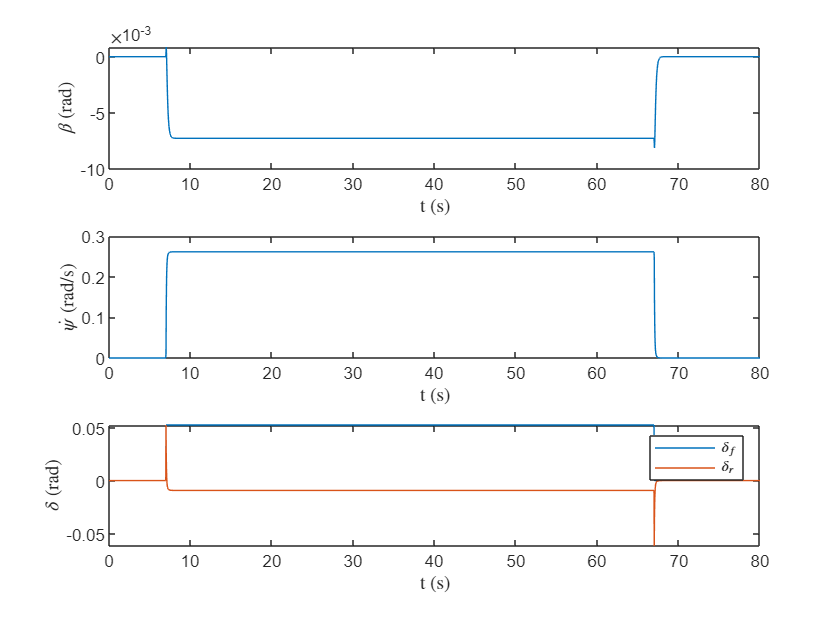

% Modify Velocity for Step Maneuver
v_step = 74/3; % mph
v_step = v_step/2.237; % m/s
% Single-Track Model
a11 = -((C_alpha_F+C_alpha_R)/(m*v_step));
a12 = -(((C_alpha_F*m_a)-(C_alpha_R*m_b))/(m*v_step^2))-1;
a21 = ((C_alpha_R*m_b)-(C_alpha_F*m_a))/(Iz);
a22 = -((C_alpha_F*m_a^2)+(C_alpha_R*m_b^2))/(Iz*v_step);
b11 = (C_alpha_F)/(m*v_step);
b12 = (C_alpha_R)/(m*v_step);
b21 = (C_alpha_F*m_a)/(Iz);
b22 = -(C_alpha_R*m_b)/(Iz);
A = [a11 a12; a21 a22];
B = [b11 b12; b21 b22];
% Initialization
dt = 0.001; % s
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
B_dot = 0;
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;
delta_r = [];
delta_r(1) = 0;
a_y = [];
% Simulation at each millisecond
for t=1:80000
    a_y(t) = v_step*(X(2,t)-B_dot);
    X_dot(:,t) = A*X(:,t)+B*[u_step(t); -delta_r(t)];
    B_dot = X_dot(1,t);
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    delta_r(t+1) = u_step(t) - (X(2,t)*l/v_step);
    alpha_f(t) = u_step(t) - (X(2,t)*m_a_i)/v_step - X(1,t);
    alpha_r(t) = delta_r(t) + (X(2,t)*m_b_i)/v_step - X(1,t);
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v_step*cos(Psi(t)+Beta(t));
    Vy(t) = v_step*sin(Psi(t)+Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
delta_r = delta_r(1:end-1);
% Plot states
t=1:80000;
figure()
subplot(3,1,1)
plot(t/1000,X(1,1:end-1))
xlabel("t (s)","Interpreter","latex")
ylabel("$\beta$ (rad)","Interpreter","latex")
subplot(3,1,2)
plot(t/1000,X(2,1:end-1))
xlabel("t (s)","Interpreter","latex")
ylabel("$\dot{\psi}$ (rad/s)","Interpreter","latex")
subplot(3,1,3)
plot(t/1000,u_step)
hold on
plot(t/1000,delta_r)
hold off
xlabel("t (s)","Interpreter","latex")
ylabel("$\delta$ (rad)","Interpreter","latex")
legend("$\delta_f$","$\delta_r$","Interpreter","latex")

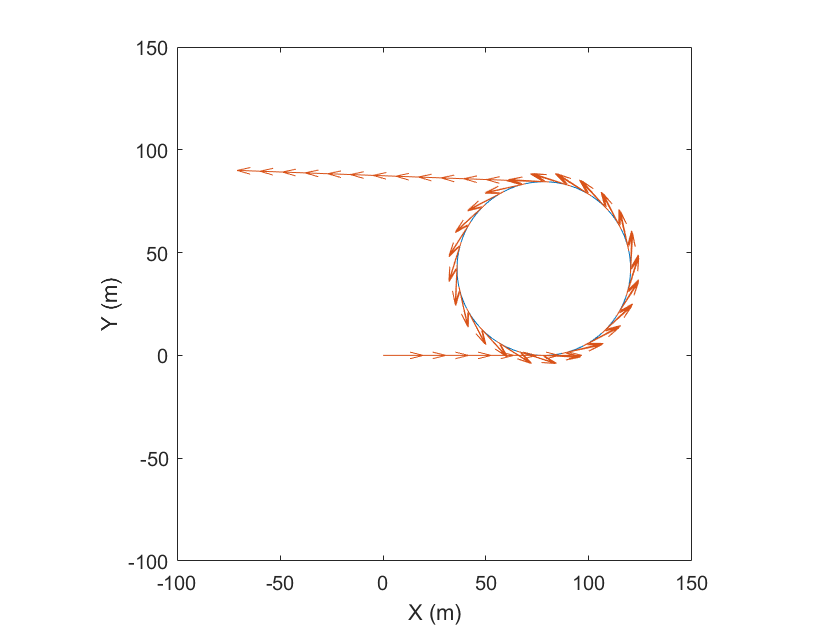

% Plot trajectory
figure()
plot(Px(1:end-1),Py(1:end-1))
hold on;
quiver(Px(1:1000:end-1000),Py(1:1000:end-1000),Vx(1:1000:end),Vy(1:1000:end))
hold off;
xlabel("X (m)")
ylabel("Y (m)")
xlim([-100,150])
ylim([-100,150])
pbaspect([1 1 1])

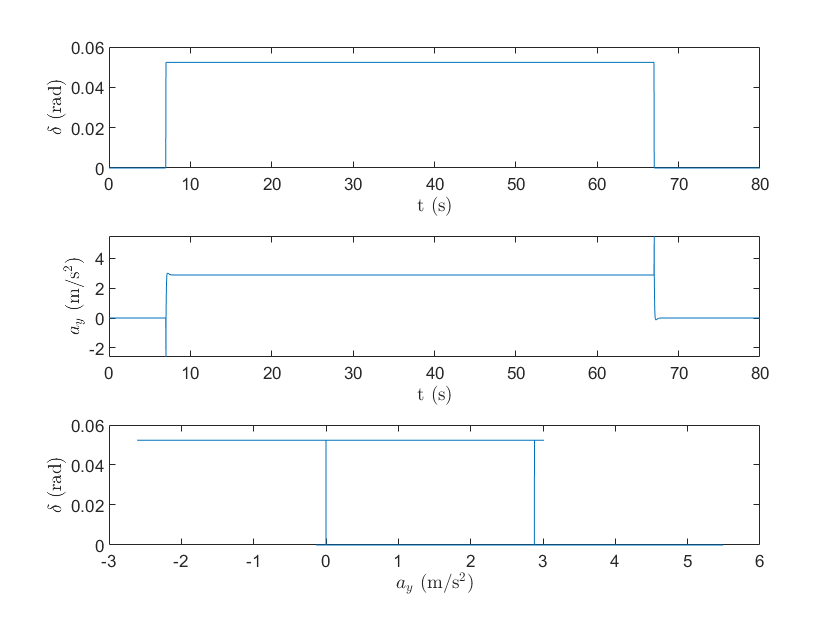

% Understeer gradient
t = 1:80000;
figure()
subplot(3,1,1)
plot(t/1000,u_step)
xlabel("t (s)","Interpreter","latex")
ylabel("$\delta$ (rad)","Interpreter","latex")
subplot(3,1,2)
plot(t/1000,a_y)
xlabel("t (s)","Interpreter","latex")
ylabel("$a_y$ (m/s$^2$)","Interpreter","latex")
subplot(3,1,3)
plot(a_y,u_step)
hold off;
xlabel("$a_y$ (m/s$^2$)","Interpreter","latex")
ylabel("$\delta$ (rad)","Interpreter","latex")

UG = (alpha_f(21000)-alpha_r(21000))/a_y(21000);
fprintf("UG for step maneuver with linear tire model, without load transfer is %.1f rad-s^2/m", UG);

UG for step maneuver with linear tire model, without load transfer is 0.0 rad-s^2/m

2. Fishhook Maneuver

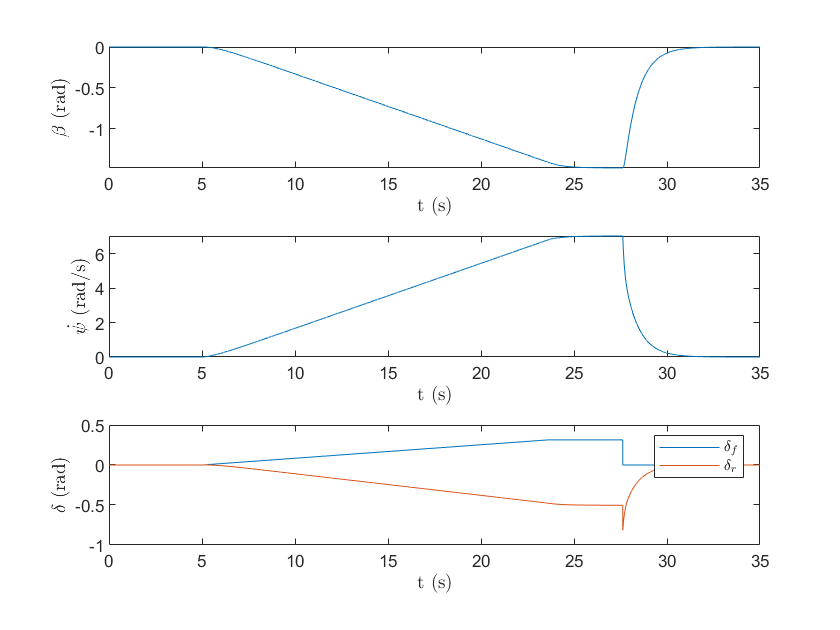

% Single-Track Model
a11 = -((C_alpha_F+C_alpha_R)/(m*v_fishhook));
a12 = -(((C_alpha_F*m_a)-(C_alpha_R*m_b))/(m*v_fishhook^2))-1;
a21 = ((C_alpha_R*m_b)-(C_alpha_F*m_a))/(Iz);
a22 = -((C_alpha_F*m_a^2)+(C_alpha_R*m_b^2))/(Iz*v_fishhook);
b11 = (C_alpha_F)/(m*v_fishhook);
b12 = (C_alpha_R)/(m*v_fishhook);
b21 = (C_alpha_F*m_a)/(Iz);
b22 = -(C_alpha_R*m_b)/(Iz);
A = [a11 a12; a21 a22];
B = [b11 b12; b21 b22];
% Initialization
dt = 0.001; % s
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
B_dot = 0;
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;
delta_r = [];
delta_r(1) = 0;
a_y = [];
% Simulation at each millisecond
for t=1:35000
    a_y(t) = v_fishhook*(X(2,t)-B_dot);
    X_dot(:,t) = A*X(:,t)+B*[u_fishhook(t); -delta_r(t)];
    B_dot = X_dot(1,t);
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    delta_r(t+1) = u_fishhook(t) - (X(2,t)*l/v_fishhook);
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v_fishhook*cos(Psi(t)+Beta(t));
    Vy(t) = v_fishhook*sin(Psi(t)+Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
delta_r = delta_r(1:end-1);
% Plot states
t=1:35000;
figure()
subplot(3,1,1)
plot(t/1000,X(1,1:end-1))
xlabel("t (s)","Interpreter","latex")
ylabel("$\beta$ (rad)","Interpreter","latex")
subplot(3,1,2)
plot(t/1000,X(2,1:end-1))
xlabel("t (s)","Interpreter","latex")
ylabel("$\dot{\psi}$ (rad/s)","Interpreter","latex")
subplot(3,1,3)
plot(t/1000,u_fishhook)
hold on
plot(t/1000,delta_r)
hold off
xlabel("t (s)","Interpreter","latex")
ylabel("$\delta$ (rad)","Interpreter","latex")
legend("$\delta_f$","$\delta_r$","Interpreter","latex")

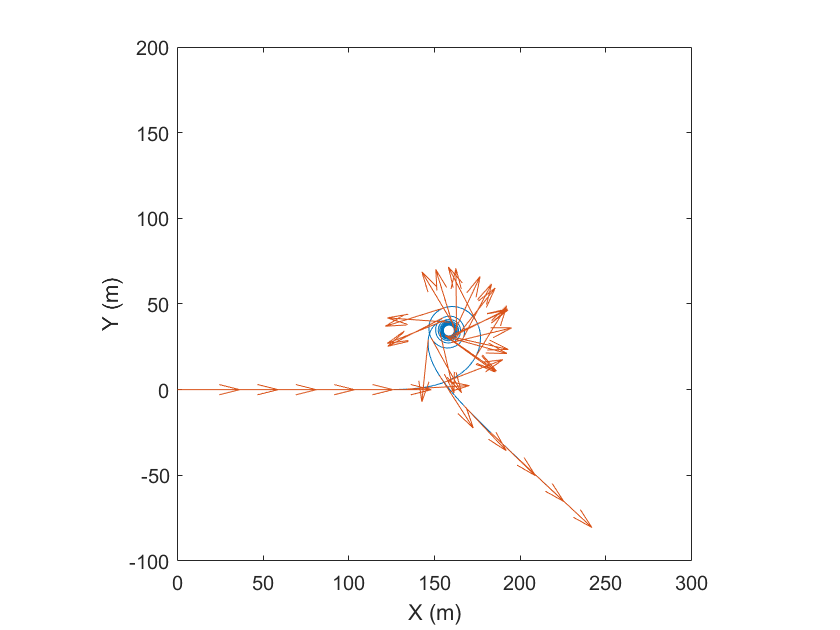

% Plot trajectory
figure()
plot(Px(1:end-1),Py(1:end-1))
hold on;
quiver(Px(1:1000:end-1000),Py(1:1000:end-1000),Vx(1:1000:end),Vy(1:1000:end))
hold off;
xlabel("X (m)")
ylabel("Y (m)")
xlim([0,300])
ylim([-100,200])
pbaspect([1 1 1])

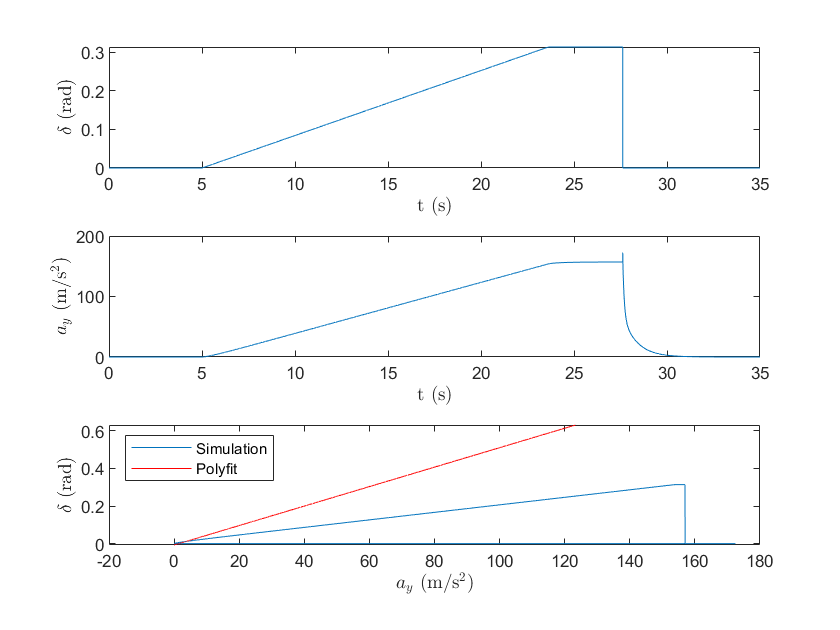

% Understeer gradient
t = 1:35000;
figure()
subplot(3,1,1)
plot(t/1000,u_fishhook-delta_r(:,end-1))
xlabel("t (s)","Interpreter","latex")
ylabel("$\delta$ (rad)","Interpreter","latex")
subplot(3,1,2)
plot(t/1000,a_y)
xlabel("t (s)","Interpreter","latex")
ylabel("$a_y$ (m/s$^2$)","Interpreter","latex")
subplot(3,1,3)
plot(a_y,u_fishhook-delta_r(:,end-1))
hold on;
UG_poly = polyfit(a_y(5000:20000), u_fishhook(5000:20000)-delta_r(5000:20000), 1);
plot(a_y(5000:20000),polyval(UG_poly,a_y(5000:20000)),'r');
hold off;
xlabel("$a_y$ (m/s$^2$)","Interpreter","latex")
ylabel("$\delta$ (rad)","Interpreter","latex")
legend("Simulation","Polyfit",'Location','NW')

UG = polyder(UG_poly) - l/(v_fishhook^2);
fprintf("UG for fishhook maneuver with linear tire model, without load transfer is %.4f rad-s^2/m\n", UG);

UG for fishhook maneuver with linear tire model, without load transfer is -0.0000 rad-s^2/m


**Part B**

1. Step Maneuver with Non-Linear Tire Model Considering Load Transfer and Roll Dynamics

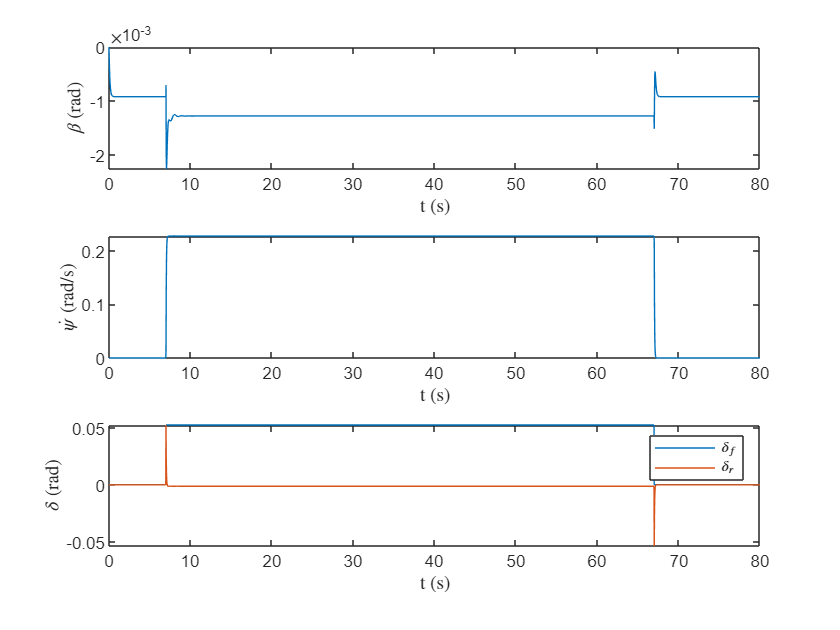

% Modify Velocity for Step Maneuver
v_step = 74/3; % mph
v_step = v_step/2.237; % m/s
% Initialization
dt = 0.001; % s
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
B_dot = 0;
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;
Phi = [];
Phi(1) = 0;
Phi_dot = [];
Phi_dot(1) = 0;
Phi_ddot = [];
delta_r = [];
delta_r(1) = 0;
alpha_f = [];
alpha_r = [];
a_y = [];
% Static load
S_fl = 0.5*(m_b/l)*m*9.81;
S_fr = 0.5*(m_b/l)*m*9.81;
S_rl = 0.5*(m_a/l)*m*9.81;
S_rr = 0.5*(m_a/l)*m*9.81;
% Simulation at each millisecond
for t=1:80000
    a_y(t) = v_step*(X(2,t)+B_dot);
    Phi_ddot(t) = (1/Ix)*(m*a_y(t)*h_cr + m*9.81*h_cr*Phi(t) - B_R*Phi_dot(t) - k_SR*Phi(t));
    Phi_dot(t+1) = Phi_dot(t) + Phi_ddot(t)*dt;
    Phi(t+1) = Phi(t) + Phi_dot(t)*dt;
    dW_f = (r_a*k_SR*Phi(t))/w + m*a_y(t)*(m_b/l)*(h_f/w);
    dW_r = (r_b*k_SR*Phi(t))/w + m*a_y(t)*(m_a/l)*(h_r/w);
    Fz_fl = S_fl - dW_f;
    Fz_fr = S_fr + dW_f;
    Fz_rl = S_rl - dW_r;
    Fz_rr = S_rr + dW_r;
    delta_r(t+1) = u_step(t) - (X(2,t)*l/v_step);
    alpha_f(t) = u_step(t) - (X(2,t)*m_a)/v_step - X(1,t);
    alpha_r(t) = -delta_r(t) + (X(2,t)*m_b)/v_step - X(1,t);
    Fy_fl = -nonlintire(alpha_f(t), Fz_fl, v_step);
    Fy_fr = -nonlintire(alpha_f(t), Fz_fr, v_step);
    Fy_rl = -nonlintire(alpha_r(t), Fz_rl, v_step);
    Fy_rr = -nonlintire(alpha_r(t), Fz_rr, v_step);
    Fy_f = Fy_fl+Fy_fr;
    Fy_r = Fy_rl+Fy_rr;
    X_dot(:,t) = [(Fy_f+Fy_r)/(m*v_step) - X(2,t);
                  (Fy_f*m_a-Fy_r*m_b)/(Iz)];
    B_dot = X_dot(1,t);
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v_step*cos(Psi(t)+Beta(t));
    Vy(t) = v_step*sin(Psi(t)+Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
delta_r = delta_r(1:end-1);
% Plot states
t=1:80000;
figure()
subplot(3,1,1)
plot(t/1000,X(1,1:end-1))
xlabel("t (s)","Interpreter","latex")
ylabel("$\beta$ (rad)","Interpreter","latex")
subplot(3,1,2)
plot(t/1000,X(2,1:end-1))
xlabel("t (s)","Interpreter","latex")
ylabel("$\dot{\psi}$ (rad/s)","Interpreter","latex")
subplot(3,1,3)
plot(t/1000,u_step)
hold on
plot(t/1000,delta_r)
hold off
xlabel("t (s)","Interpreter","latex")
ylabel("$\delta$ (rad)","Interpreter","latex")
legend("$\delta_f$","$\delta_r$","Interpreter","latex")

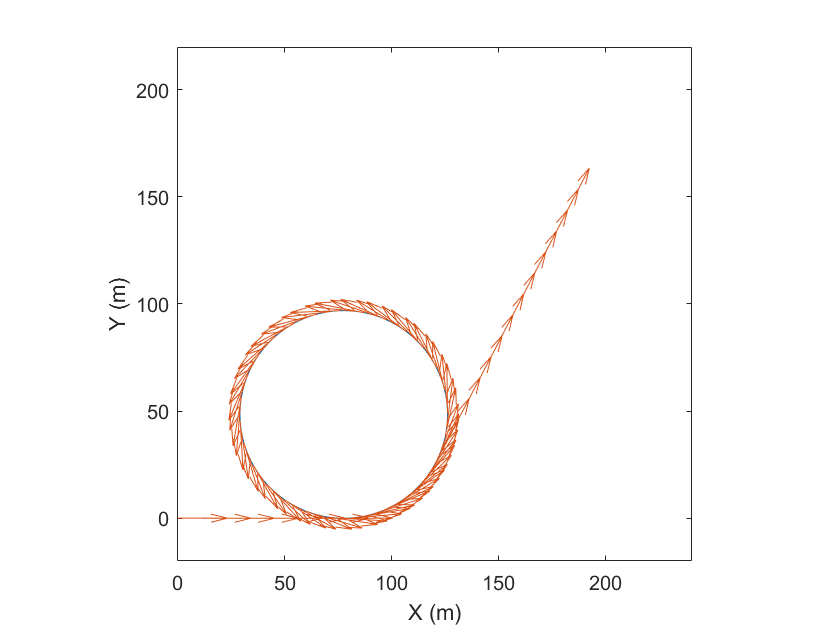

% Plot trajectory
figure()
plot(Px(1:end-1),Py(1:end-1))
hold on;
quiver(Px(1:1000:end-1000),Py(1:1000:end-1000),Vx(1:1000:end),Vy(1:1000:end))
hold off;
xlabel("X (m)")
ylabel("Y (m)")
xlim([0,240])
ylim([-20,220])
pbaspect([1 1 1])

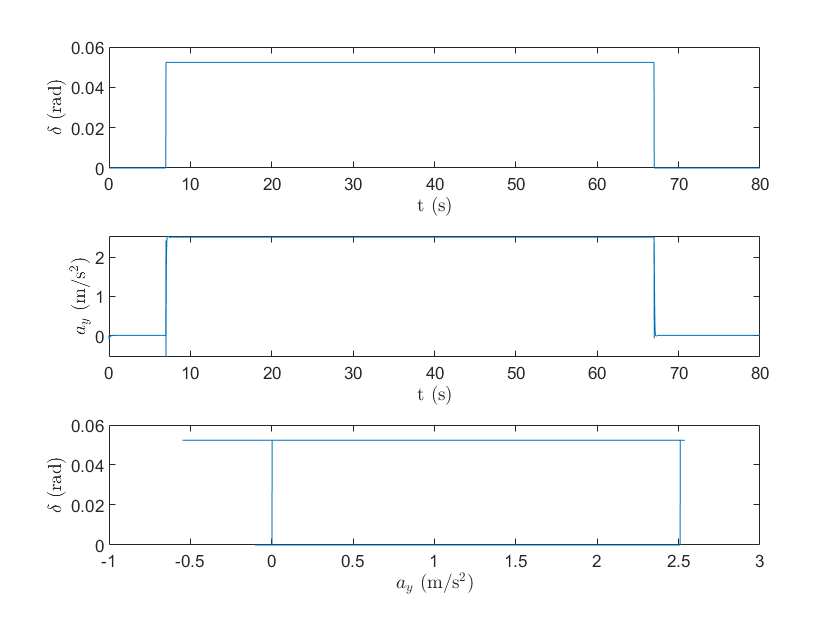

% Understeer gradient
t = 1:80000;
figure()
subplot(3,1,1)
plot(t/1000,u_step)
xlabel("t (s)","Interpreter","latex")
ylabel("$\delta$ (rad)","Interpreter","latex")
subplot(3,1,2)
plot(t/1000,a_y)
xlabel("t (s)","Interpreter","latex")
ylabel("$a_y$ (m/s$^2$)","Interpreter","latex")
subplot(3,1,3)
plot(a_y,u_step)
hold off;
xlabel("$a_y$ (m/s$^2$)","Interpreter","latex")
ylabel("$\delta$ (rad)","Interpreter","latex")

UG = (alpha_f(21000)-alpha_r(21000))/a_y(21000);
fprintf("UG for step maneuver with non-linear tire model, with load transfer is %.1f rad-s^2/m", UG);

UG for step maneuver with non-linear tire model, with load transfer is -0.0 rad-s^2/m

2. Fishhook Maneuver with Non-Linear Tire Model Considering Load Transfer and Roll Dynamics

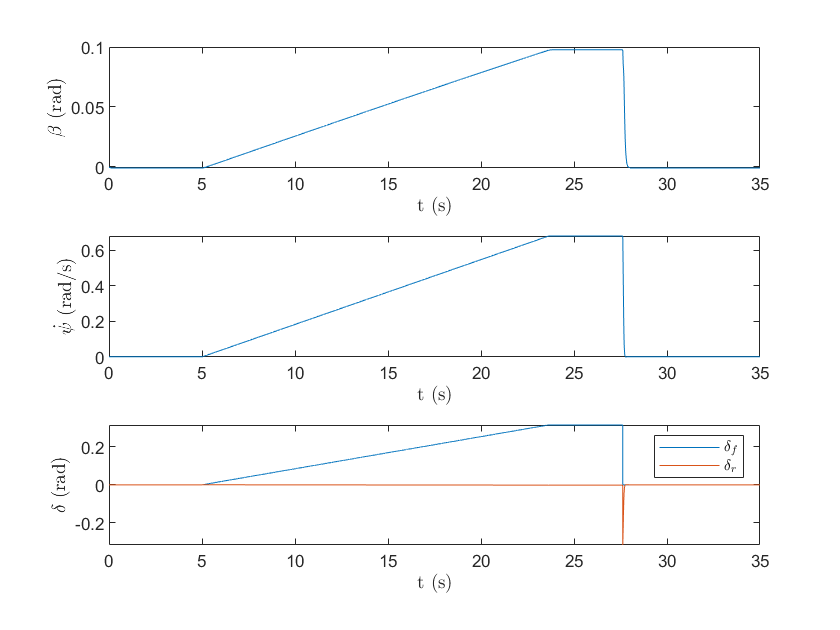

% Modify Velocity for Step Maneuver
v_fishhook = 50/4; % mph
v_fishhook = v_fishhook/2.237; % m/s
% Initialization
dt = 0.001; % s
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
B_dot = 0;
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;
Phi = [];
Phi(1) = 0;
Phi_dot = [];
Phi_dot(1) = 0;
Phi_ddot = [];
delta_r = [];
delta_r(1) = 0;
alpha_f = [];
alpha_r = [];
a_y = [];
% Static load
S_fl = 0.5*(m_b/l)*m*9.81;
S_fr = 0.5*(m_b/l)*m*9.81;
S_rl = 0.5*(m_a/l)*m*9.81;
S_rr = 0.5*(m_a/l)*m*9.81;
% Simulation at each millisecond
for t=1:35000
    a_y(t) = v_fishhook*(X(2,t)+B_dot);
    Phi_ddot(t) = (1/Ix)*(m*a_y(t)*h_cr + m*9.81*h_cr*Phi(t) - B_R*Phi_dot(t) - k_SR*Phi(t));
    Phi_dot(t+1) = Phi_dot(t) + Phi_ddot(t)*dt;
    Phi(t+1) = Phi(t) + Phi_dot(t)*dt;
    dW_f = (r_a*k_SR*Phi(t))/w + m*a_y(t)*(m_b/l)*(h_f/w);
    dW_r = (r_b*k_SR*Phi(t))/w + m*a_y(t)*(m_a/l)*(h_r/w);
    Fz_fl = S_fl - dW_f;
    Fz_fr = S_fr + dW_f;
    Fz_rl = S_rl - dW_r;
    Fz_rr = S_rr + dW_r;
    delta_r(t+1) = u_fishhook(t) - (X(2,t)*l/v_fishhook);
    alpha_f(t) = u_fishhook(t) - (X(2,t)*m_a)/v_fishhook - X(1,t);
    alpha_r(t) = -delta_r(t) + (X(2,t)*m_b)/v_fishhook - X(1,t);
    Fy_fl = -nonlintire(alpha_f(t), Fz_fl, v_fishhook);
    Fy_fr = -nonlintire(alpha_f(t), Fz_fr, v_fishhook);
    Fy_rl = -nonlintire(alpha_r(t), Fz_rl, v_fishhook);
    Fy_rr = -nonlintire(alpha_r(t), Fz_rr, v_fishhook);
    Fy_f = Fy_fl+Fy_fr;
    Fy_r = Fy_rl+Fy_rr;
    X_dot(:,t) = [(Fy_f+Fy_r)/(m*v_fishhook) - X(2,t);
                  (Fy_f*m_a-Fy_r*m_b)/(Iz)];
    B_dot = X_dot(1,t);
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v_fishhook*cos(Psi(t)+Beta(t));
    Vy(t) = v_fishhook*sin(Psi(t)+Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
delta_r = delta_r(1:end-1);
% Plot states
t=1:35000;
figure()
subplot(3,1,1)
plot(t/1000,X(1,1:end-1))
xlabel("t (s)","Interpreter","latex")
ylabel("$\beta$ (rad)","Interpreter","latex")
subplot(3,1,2)
plot(t/1000,X(2,1:end-1))
xlabel("t (s)","Interpreter","latex")
ylabel("$\dot{\psi}$ (rad/s)","Interpreter","latex")
subplot(3,1,3)
plot(t/1000,u_fishhook)
hold on
plot(t/1000,delta_r)
hold off
xlabel("t (s)","Interpreter","latex")
ylabel("$\delta$ (rad)","Interpreter","latex")
legend("$\delta_f$","$\delta_r$","Interpreter","latex")

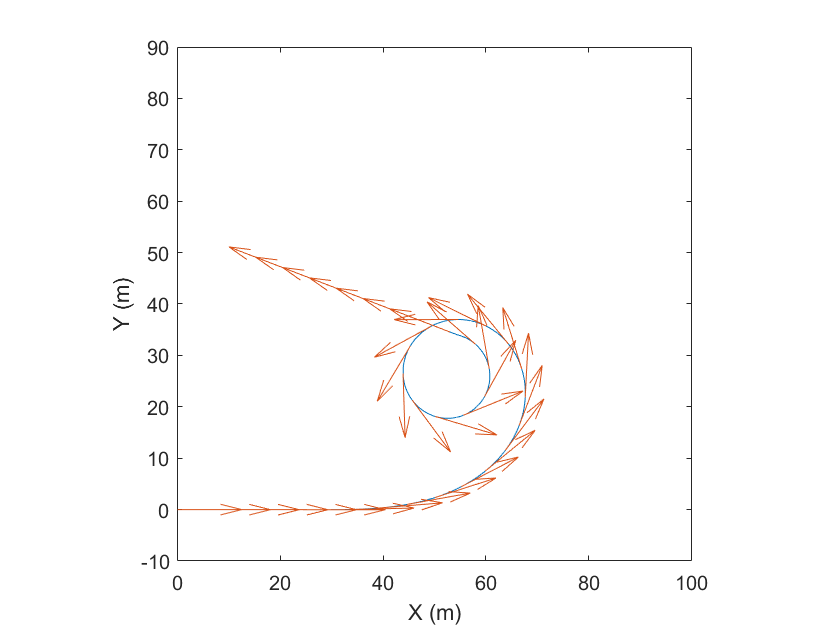

% Plot trajectory
figure()
plot(Px(1:end-1),Py(1:end-1))
hold on;
quiver(Px(1:1000:end-1000),Py(1:1000:end-1000),Vx(1:1000:end),Vy(1:1000:end))
hold off;
xlabel("X (m)")
ylabel("Y (m)")
xlim([0,100])
ylim([-10,90])
pbaspect([1 1 1])

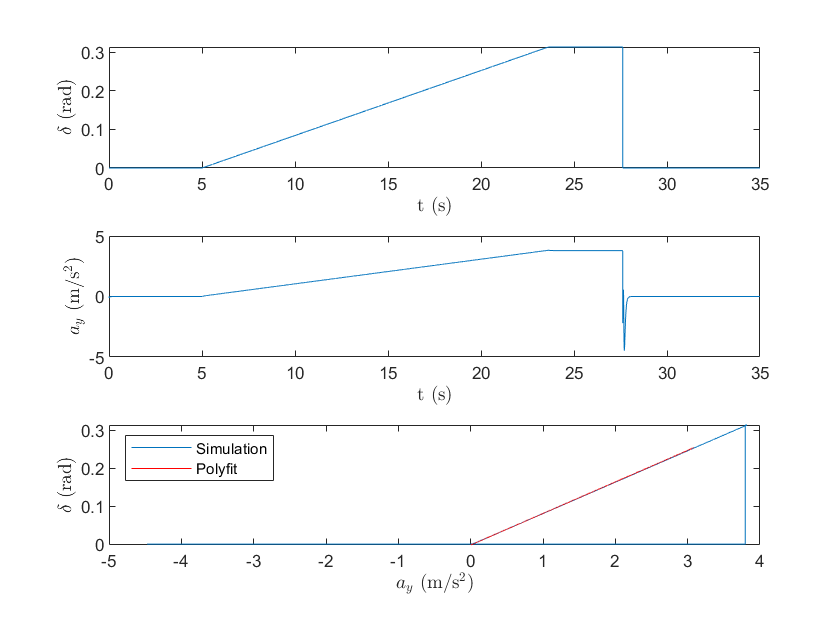

% Understeer gradient
t = 1:35000;
figure()
subplot(3,1,1)
plot(t/1000,u_fishhook-delta_r(:,end-1))
xlabel("t (s)","Interpreter","latex")
ylabel("$\delta$ (rad)","Interpreter","latex")
subplot(3,1,2)
plot(t/1000,a_y)
xlabel("t (s)","Interpreter","latex")
ylabel("$a_y$ (m/s$^2$)","Interpreter","latex")
subplot(3,1,3)
plot(a_y,u_fishhook-delta_r(:,end-1))
hold on;
UG_poly = polyfit(a_y(5000:20000), u_fishhook(5000:20000)-delta_r(5000:20000), 1);
plot(a_y(5000:20000),polyval(UG_poly,a_y(5000:20000)),'r');
hold off;
xlabel("$a_y$ (m/s$^2$)","Interpreter","latex")
ylabel("$\delta$ (rad)","Interpreter","latex")
legend("Simulation","Polyfit",'Location','NW')

UG = polyder(UG_poly) - l/(v_fishhook^2);
fprintf("UG for fishhook maneuver with linear tire model, without load transfer is %.4f rad-s^2/m\n", UG);

UG for fishhook maneuver with linear tire model, without load transfer is 0.0000 rad-s^2/m


### PART IV - FOUR-WHEEL MODEL

Now, we want to expand the model into a 4-wheel model while still considering 4 DoFs. Figure below provides a corresponding diagram for a 4-wheel model with front axle steering

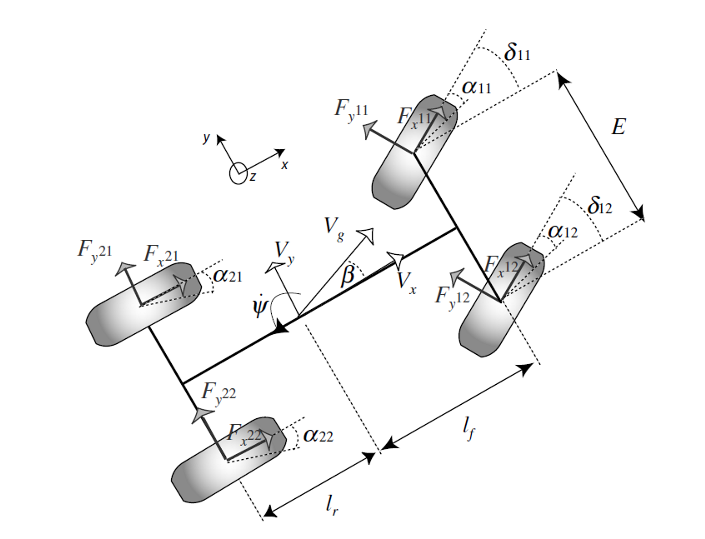

A. Derive an updated vehicle model for x, y, and ψ motion for a four-wheel model only with rear axle steering using above figure as a reference.

B. Derive updated equation for the wheel velocity in the x-direction of each wheel’s coordinate system as well as expressions for the 4 individual slip angles. You might find the following figure useful:

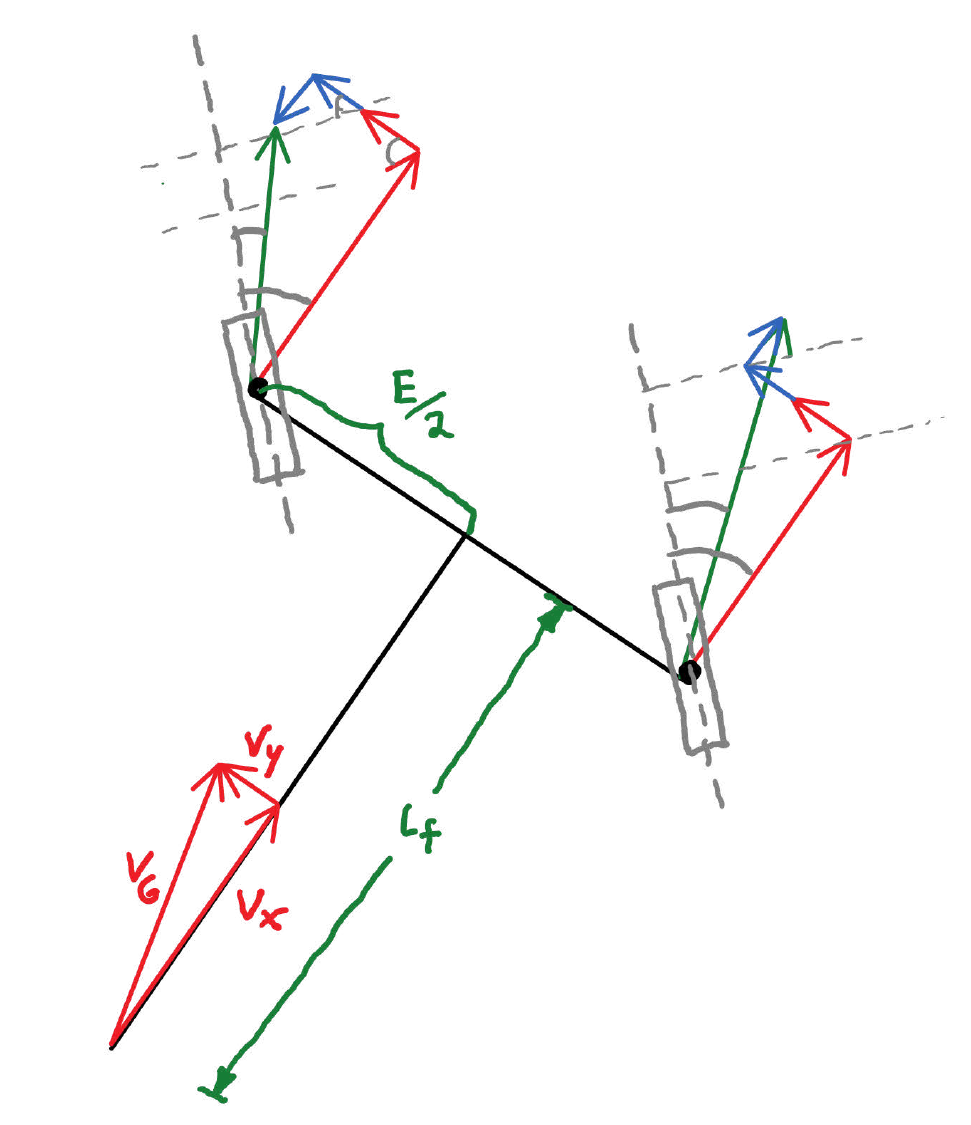

C.Develop the model considering Ackermann geometry at road wheel angle for left and right tires.

        a. Perform the simulation for fishhook maneuver.

        b. Toe-out of 0.5 deg at front wheels. Perform the simulation for fishhook maneuver. Compare the performance of model with toe to without toe. Provide the explanation.

### Solution IV

**Part C**

1. Simulation for Fishhook Maneuver without Toe

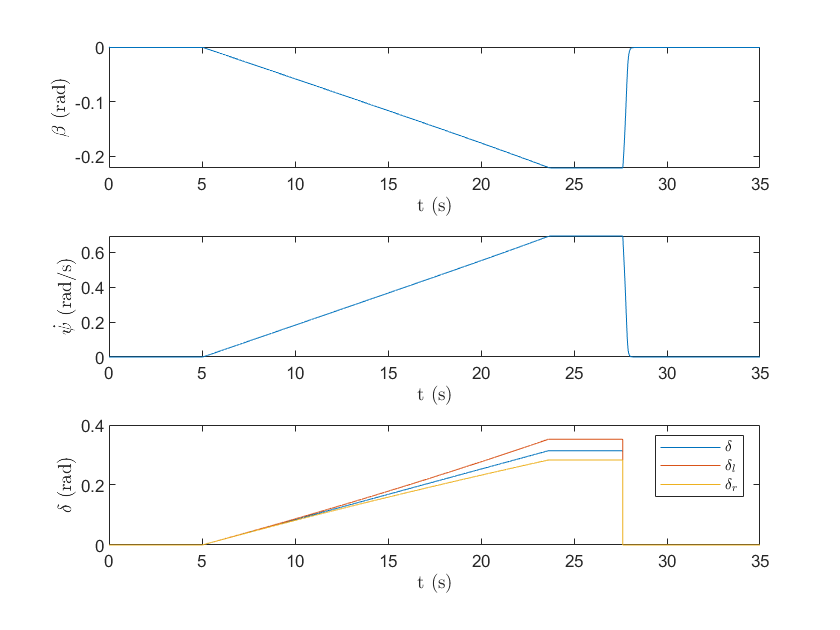

% Modify Velocity for Step Maneuver
v_fishhook = 50/4; % mph
v_fishhook = v_fishhook/2.237; % m/s
% Initialization
dt = 0.001; % s
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
B_dot = 0;
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;
Phi = [];
Phi(1) = 0;
Phi_dot = [];
Phi_dot(1) = 0;
Phi_ddot = [];
delta_rl = [];
delta_rl(1) = 0;
delta_rr = [];
delta_rr(1) = 0;
alpha_fl = [];
alpha_fr = [];
alpha_rl = [];
alpha_rr = [];
a_y = [];
% Static load
S_fl = 0.5*(m_b/l)*m*9.81;
S_fr = 0.5*(m_b/l)*m*9.81;
S_rl = 0.5*(m_a/l)*m*9.81;
S_rr = 0.5*(m_a/l)*m*9.81;
% Simulation at each millisecond
for t=1:35000
    a_y(t) = v_fishhook*(X(2,t)+B_dot);
    Phi_ddot(t) = (1/Ix)*(m*a_y(t)*h_cr + m*9.81*h_cr*Phi(t) - B_R*Phi_dot(t) - k_SR*Phi(t));
    Phi_dot(t+1) = Phi_dot(t) + Phi_ddot(t)*dt;
    Phi(t+1) = Phi(t) + Phi_dot(t)*dt;
    dW_f = (r_a*k_SR*Phi(t))/w + m*a_y(t)*(m_b/l)*(h_f/w);
    dW_r = (r_b*k_SR*Phi(t))/w + m*a_y(t)*(m_a/l)*(h_r/w);
    Fz_fl = S_fl - dW_f;
    Fz_fr = S_fr + dW_f;
    Fz_rl = S_rl - dW_r;
    Fz_rr = S_rr + dW_r;
    delta_rl(t+1) = l/(l/u_fishhook(t) - w/2);
    delta_rr(t+1) = l/(l/u_fishhook(t) + w/2);
    alpha_fl(t) = -(X(2,t)*m_a)/v_fishhook - X(1,t);
    alpha_fr(t) = -(X(2,t)*m_a)/v_fishhook - X(1,t);
    alpha_rl(t) = -delta_rl(t) + (X(2,t)*m_b)/v_fishhook - X(1,t);
    alpha_rr(t) = -delta_rr(t) + (X(2,t)*m_b)/v_fishhook - X(1,t);
    Fy_fl = -nonlintire(alpha_fl(t), Fz_fl, v_fishhook);
    Fy_fr = -nonlintire(alpha_fr(t), Fz_fr, v_fishhook);
    Fy_rl = -nonlintire(alpha_rl(t), Fz_rl, v_fishhook);
    Fy_rr = -nonlintire(alpha_rr(t), Fz_rr, v_fishhook);
    Fy_f = Fy_fl+Fy_fr;
    Fy_r = Fy_rl+Fy_rr;
    X_dot(:,t) = [(Fy_f+Fy_r)/(m*v_fishhook) - X(2,t);
                  (Fy_f*m_a-Fy_r*m_b)/(Iz)];
    B_dot = X_dot(1,t);
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v_fishhook*cos(Psi(t)+Beta(t));
    Vy(t) = v_fishhook*sin(Psi(t)+Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
delta_rl = delta_rl(1:end-1);
delta_rr = delta_rr(1:end-1);
% Plot states
t=1:35000;
figure()
subplot(3,1,1)
plot(t/1000,X(1,1:end-1))
xlabel("t (s)","Interpreter","latex")
ylabel("$\beta$ (rad)","Interpreter","latex")
subplot(3,1,2)
plot(t/1000,X(2,1:end-1))
xlabel("t (s)","Interpreter","latex")
ylabel("$\dot{\psi}$ (rad/s)","Interpreter","latex")
subplot(3,1,3)
plot(t/1000,u_fishhook)
hold on
plot(t/1000,delta_rl)
plot(t/1000,delta_rr)
hold off
xlabel("t (s)","Interpreter","latex")
ylabel("$\delta$ (rad)","Interpreter","latex")
legend("$\delta$","$\delta_l$","$\delta_r$","Interpreter","latex")

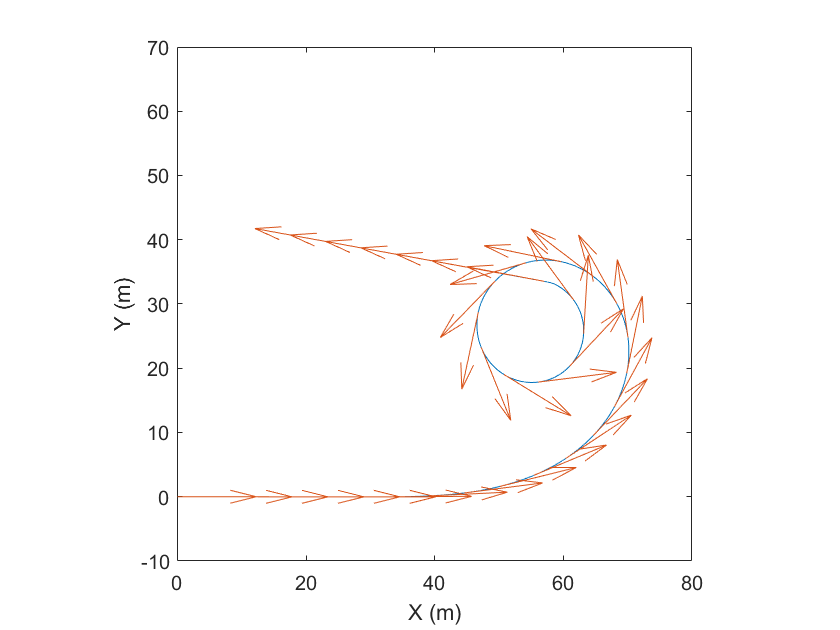

% Plot trajectory
figure()
plot(Px(1:end-1),Py(1:end-1))
hold on;
quiver(Px(1:1000:end-1000),Py(1:1000:end-1000),Vx(1:1000:end),Vy(1:1000:end))
hold off;
xlabel("X (m)")
ylabel("Y (m)")
xlim([0,80])
ylim([-10,70])
pbaspect([1 1 1])

2. Simulation for Fishhook Maneuver with Toe

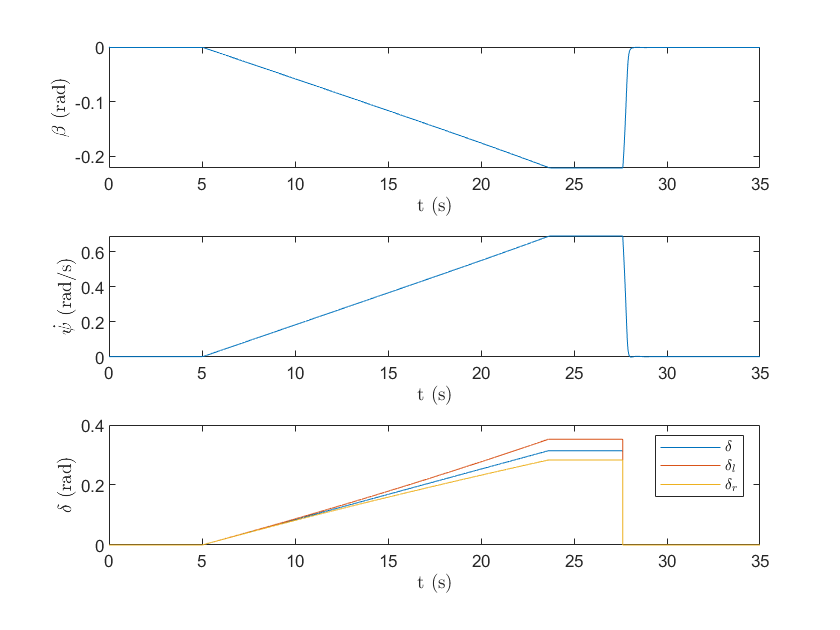

% Toe angle
delta_toe = 0.5; % deg
delta_toe = deg2rad(delta_toe); % rad
% Modify Velocity for Step Maneuver
v_fishhook = 50/4; % mph
v_fishhook = v_fishhook/2.237; % m/s
% Initialization
dt = 0.001; % s
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
B_dot = 0;
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;
Phi = [];
Phi(1) = 0;
Phi_dot = [];
Phi_dot(1) = 0;
Phi_ddot = [];
delta_rl = [];
delta_rl(1) = 0;
delta_rr = [];
delta_rr(1) = 0;
alpha_fl = [];
alpha_fr = [];
alpha_rl = [];
alpha_rr = [];
a_y = [];
% Static load
S_fl = 0.5*(m_b/l)*m*9.81;
S_fr = 0.5*(m_b/l)*m*9.81;
S_rl = 0.5*(m_a/l)*m*9.81;
S_rr = 0.5*(m_a/l)*m*9.81;
% Simulation at each millisecond
for t=1:35000
    a_y(t) = v_fishhook*(X(2,t)+B_dot);
    Phi_ddot(t) = (1/Ix)*(m*a_y(t)*h_cr + m*9.81*h_cr*Phi(t) - B_R*Phi_dot(t) - k_SR*Phi(t));
    Phi_dot(t+1) = Phi_dot(t) + Phi_ddot(t)*dt;
    Phi(t+1) = Phi(t) + Phi_dot(t)*dt;
    dW_f = (r_a*k_SR*Phi(t))/w + m*a_y(t)*(m_b/l)*(h_f/w);
    dW_r = (r_b*k_SR*Phi(t))/w + m*a_y(t)*(m_a/l)*(h_r/w);
    Fz_fl = S_fl - dW_f;
    Fz_fr = S_fr + dW_f;
    Fz_rl = S_rl - dW_r;
    Fz_rr = S_rr + dW_r;
    delta_rl(t+1) = l/(l/u_fishhook(t) - w/2);
    delta_rr(t+1) = l/(l/u_fishhook(t) + w/2);
    alpha_fl(t) = -(X(2,t)*m_a)/v_fishhook - X(1,t) + delta_toe;
    alpha_fr(t) = -(X(2,t)*m_a)/v_fishhook - X(1,t) - delta_toe;
    alpha_rl(t) = -delta_rl(t) + (X(2,t)*m_b)/v_fishhook - X(1,t);
    alpha_rr(t) = -delta_rr(t) + (X(2,t)*m_b)/v_fishhook - X(1,t);
    Fy_fl = -nonlintire(alpha_fl(t), Fz_fl, v_fishhook);
    Fy_fr = -nonlintire(alpha_fr(t), Fz_fr, v_fishhook);
    Fy_rl = -nonlintire(alpha_rl(t), Fz_rl, v_fishhook);
    Fy_rr = -nonlintire(alpha_rr(t), Fz_rr, v_fishhook);
    Fy_f = Fy_fl+Fy_fr;
    Fy_r = Fy_rl+Fy_rr;
    X_dot(:,t) = [(Fy_f+Fy_r)/(m*v_fishhook) - X(2,t);
                  (Fy_f*m_a-Fy_r*m_b)/(Iz)];
    B_dot = X_dot(1,t);
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v_fishhook*cos(Psi(t)+Beta(t));
    Vy(t) = v_fishhook*sin(Psi(t)+Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
delta_rl = delta_rl(1:end-1);
delta_rr = delta_rr(1:end-1);
% Plot states
t=1:35000;
figure()
subplot(3,1,1)
plot(t/1000,X(1,1:end-1))
xlabel("t (s)","Interpreter","latex")
ylabel("$\beta$ (rad)","Interpreter","latex")
subplot(3,1,2)
plot(t/1000,X(2,1:end-1))
xlabel("t (s)","Interpreter","latex")
ylabel("$\dot{\psi}$ (rad/s)","Interpreter","latex")
subplot(3,1,3)
plot(t/1000,u_fishhook)
hold on
plot(t/1000,delta_rl)
plot(t/1000,delta_rr)
hold off
xlabel("t (s)","Interpreter","latex")
ylabel("$\delta$ (rad)","Interpreter","latex")
legend("$\delta$","$\delta_l$","$\delta_r$","Interpreter","latex")

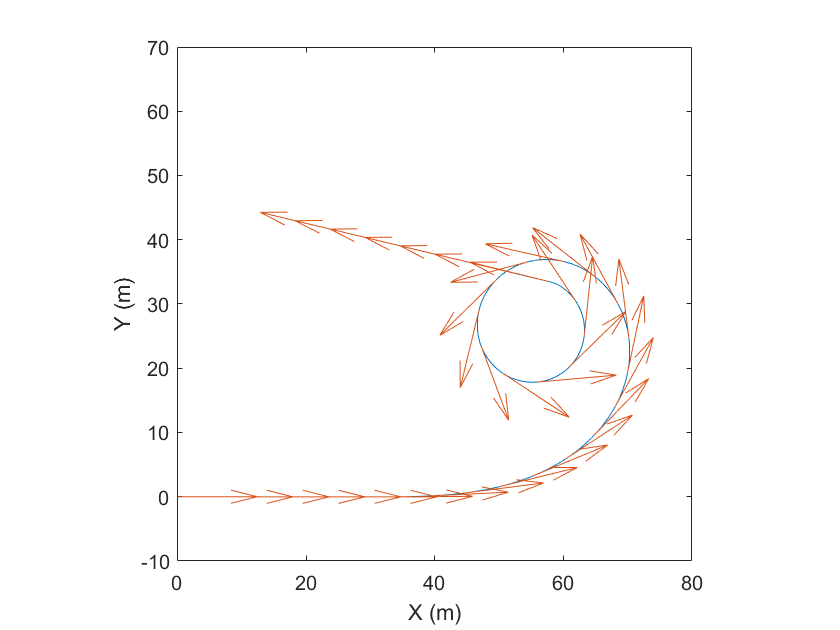

% Plot trajectory
figure()
plot(Px(1:end-1),Py(1:end-1))
hold on;
quiver(Px(1:1000:end-1000),Py(1:1000:end-1000),Vx(1:1000:end),Vy(1:1000:end))
hold off;
xlabel("X (m)")
ylabel("Y (m)")
xlim([0,80])
ylim([-10,70])
pbaspect([1 1 1])

3. Simulation for Fishhook Maneuver with Large Toe

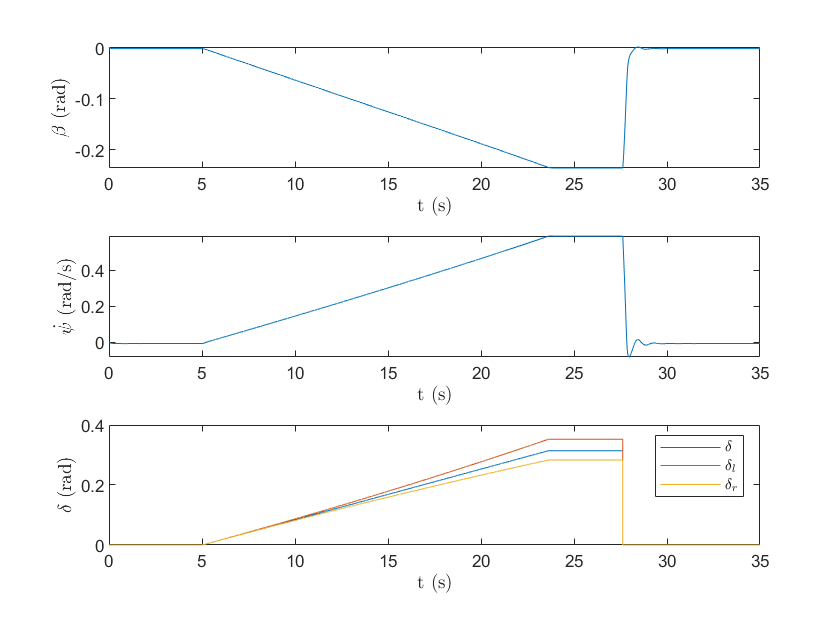

% Toe angle
delta_toe = 5; % deg
delta_toe = deg2rad(delta_toe); % rad
% Modify Velocity for Step Maneuver
v_fishhook = 50/4; % mph
v_fishhook = v_fishhook/2.237; % m/s
% Initialization
dt = 0.001; % s
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
B_dot = 0;
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;
Phi = [];
Phi(1) = 0;
Phi_dot = [];
Phi_dot(1) = 0;
Phi_ddot = [];
delta_rl = [];
delta_rl(1) = 0;
delta_rr = [];
delta_rr(1) = 0;
alpha_fl = [];
alpha_fr = [];
alpha_rl = [];
alpha_rr = [];
a_y = [];
% Static load
S_fl = 0.5*(m_b/l)*m*9.81;
S_fr = 0.5*(m_b/l)*m*9.81;
S_rl = 0.5*(m_a/l)*m*9.81;
S_rr = 0.5*(m_a/l)*m*9.81;
% Simulation at each millisecond
for t=1:35000
    a_y(t) = v_fishhook*(X(2,t)+B_dot);
    Phi_ddot(t) = (1/Ix)*(m*a_y(t)*h_cr + m*9.81*h_cr*Phi(t) - B_R*Phi_dot(t) - k_SR*Phi(t));
    Phi_dot(t+1) = Phi_dot(t) + Phi_ddot(t)*dt;
    Phi(t+1) = Phi(t) + Phi_dot(t)*dt;
    dW_f = (r_a*k_SR*Phi(t))/w + m*a_y(t)*(m_b/l)*(h_f/w);
    dW_r = (r_b*k_SR*Phi(t))/w + m*a_y(t)*(m_a/l)*(h_r/w);
    Fz_fl = S_fl - dW_f;
    Fz_fr = S_fr + dW_f;
    Fz_rl = S_rl - dW_r;
    Fz_rr = S_rr + dW_r;
    delta_rl(t+1) = l/(l/u_fishhook(t) - w/2);
    delta_rr(t+1) = l/(l/u_fishhook(t) + w/2);
    alpha_fl(t) = -(X(2,t)*m_a)/v_fishhook - X(1,t) + delta_toe;
    alpha_fr(t) = -(X(2,t)*m_a)/v_fishhook - X(1,t) - delta_toe;
    alpha_rl(t) = -delta_rl(t) + (X(2,t)*m_b)/v_fishhook - X(1,t);
    alpha_rr(t) = -delta_rr(t) + (X(2,t)*m_b)/v_fishhook - X(1,t);
    Fy_fl = -nonlintire(alpha_fl(t), Fz_fl, v_fishhook);
    Fy_fr = -nonlintire(alpha_fr(t), Fz_fr, v_fishhook);
    Fy_rl = -nonlintire(alpha_rl(t), Fz_rl, v_fishhook);
    Fy_rr = -nonlintire(alpha_rr(t), Fz_rr, v_fishhook);
    Fy_f = Fy_fl+Fy_fr;
    Fy_r = Fy_rl+Fy_rr;
    X_dot(:,t) = [(Fy_f+Fy_r)/(m*v_fishhook) - X(2,t);
                  (Fy_f*m_a-Fy_r*m_b)/(Iz)];
    B_dot = X_dot(1,t);
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v_fishhook*cos(Psi(t)+Beta(t));
    Vy(t) = v_fishhook*sin(Psi(t)+Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
delta_rl = delta_rl(1:end-1);
delta_rr = delta_rr(1:end-1);
% Plot states
t=1:35000;
figure()
subplot(3,1,1)
plot(t/1000,X(1,1:end-1))
xlabel("t (s)","Interpreter","latex")
ylabel("$\beta$ (rad)","Interpreter","latex")
subplot(3,1,2)
plot(t/1000,X(2,1:end-1))
xlabel("t (s)","Interpreter","latex")
ylabel("$\dot{\psi}$ (rad/s)","Interpreter","latex")
subplot(3,1,3)
plot(t/1000,u_fishhook)
hold on
plot(t/1000,delta_rl)
plot(t/1000,delta_rr)
hold off
xlabel("t (s)","Interpreter","latex")
ylabel("$\delta$ (rad)","Interpreter","latex")
legend("$\delta$","$\delta_l$","$\delta_r$","Interpreter","latex")

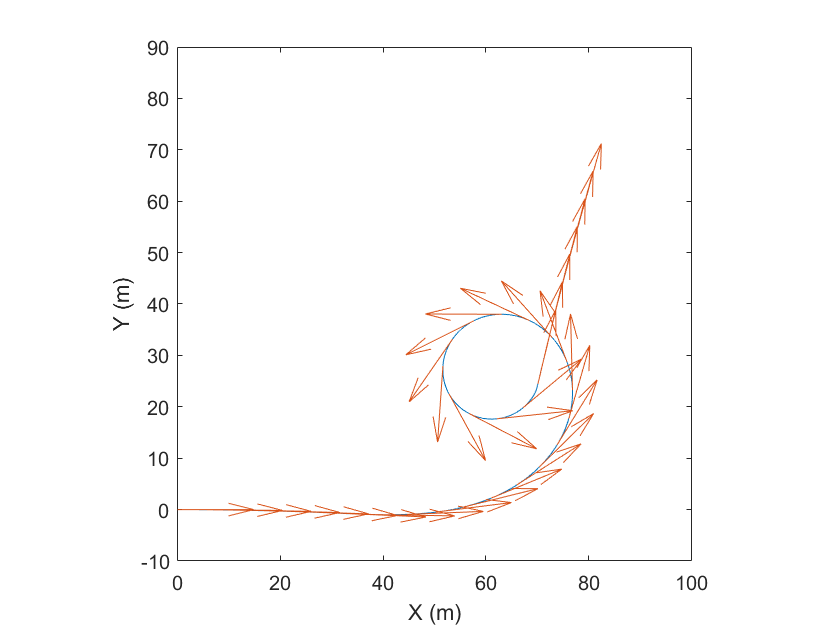

% Plot trajectory
figure()
plot(Px(1:end-1),Py(1:end-1))
hold on;
quiver(Px(1:1000:end-1000),Py(1:1000:end-1000),Vx(1:1000:end),Vy(1:1000:end))
hold off;
xlabel("X (m)")
ylabel("Y (m)")
xlim([0,100])
ylim([-10,90])
pbaspect([1 1 1])